clear 

% We need to provide the input files, which are 
% 1.A DEM.tiff file of the area (containg the grid data)
% 2.A KML file of conotur limits ( containing the boundary 

Dem_file='Frasse_Landslide_data.tif'  % put the name of Dem file in tiff formet 

Dem_file = 'frasse_data.tif'

KML_file='Frasse_Landslide_boundary.kml'  % put the name of kml file in kml formate 

KML_file = 'frasse_boundary.kml'




% 3 approaches have been discussed here for getting the failure surface and
% volume. Based on the grid data and the kml file of counture limits of landslide
% Method 1-Constant average Dip angle for entire failure surface (assumed
%          that dip angle is constant for failure surface.
% Method 2-Varying Dip anle (weightaga is given based on-
%          distance of intersection points from elevation line ). Higher the
%          distance lower the weightage for Dip and strike angle variations
%          Elevation line is horizontal projection of steepest slope.
% Method 3-Varying Dip angle(The left and right profile has been
%          assumed as an arc of big Circle) . And then the Dip angle have
%          been linearly distributed to the intersection points
% Enter any of the 3 methods in the input option to proceed further
Option=input(['Option 1-Open a saved Project Enter-1 \n' ...
             'Option 2-Open a New project Enter-2\n' ...
             'Selct one of the above\n'])

Option =           2.00


if Option==1
    [file,path] = uigetfile('*.mat')
    pro=load(file);
    Method=pro.method
    if Method==1
        Right_Dip_angle =pro.r
        Left_Dip_angle  =pro.l
    else
        Rgt.top_dip= pro.r.top_dip
        Rgt.top_strik= pro.r.top_strik
        Rgt.botm_dip= pro.r.botm_dip
        Rgt.botm_strik= pro.r.botm_strik
        
        Lft.top_dip= pro.l.top_dip
        Lft.top_strik= pro.l.top_strik
        Lft.botm_dip= pro.l.botm_dip
        Lft.botm_strik= pro.l.botm_strik
        
    end
elseif Option==2
    
    Method = input (['Method 1-Constant average Dip angle  enter-1 \n' ...
                 'Method 2-Varying Dip and strik anle (waitege based on distance from elevation line) enter-2\n' ...
                 'Method 3-Varying Dip and strike angle(each profile is an arc of big Circle) enter-3\n' ...
                'Selct one of the above\n'])
        if (Method > 3 || Method <1)
           error('Wrong selection: Please select between 1 to 3')     
        end
    
    %For calculation the strike and dip angles are required.For right profile
    %of the failure surface as well as for the left profile. Provide the
    %suitable values for selected method
    
    if (Method==1)
       Constant_Dip = inputdlg({'Enter Right profile Dip angle','Enter Left profile Dip angle'},'Constant Dip', [1 50; 1 50]) 
       Right_Dip_angle = str2double(Constant_Dip{1})
       Left_Dip_angle = str2double(Constant_Dip{2})
       
       pro.r=Right_Dip_angle;
       pro.l=Left_Dip_angle;
       pro.method=Method
       ask=input(['Press-1 to Save data entered \n' ...
           'Or Press Enter to move farwar(without saving) \n' ...
           '(use the suitable formate to title to remember the name- like-dip_strik30_40_method1)\n'])
       if ask==1
           keep=uiputfile('*.mat');
           save(keep,'-struct','pro');
       end

             
    elseif(Method==2 || Method==3) 
        Right_profile = inputdlg({' Enter Dip angle(top side)','Enter Dip angle(bottom side)'}, ...
        'Right profile', [ 1 50; 1 50],{'50','20'})
        
        Rgt.top_dip= str2double(Right_profile{1});
        Rgt.top_strik= 120; %str2double(Right_profile{2});
        Rgt.botm_dip= str2double(Right_profile{2});
        Rgt.botm_strik=240;% str2double(Right_profile{4})
        
        if Rgt.top_strik > Rgt.botm_strik
            
            error("wrong input\n Strike at the top, should be less than at the bottom")           
        end
    
        Left_profile = inputdlg({' Enter Dip angle(top side)','Enter Dip angle(bottom side)'}, ...
        'Left Profile', [1 50; 1 50],{'50','20'})
         
        Lft.top_dip= str2double(Left_profile{1});
        Lft.top_strik= 240; %str2double(Left_profile{2});
        Lft.botm_dip= str2double(Left_profile{2});
        Lft.botm_strik=120; % str2double(Left_profile{4})
        
        if Lft.top_strik < Lft.botm_strik
            error("wrong input\n Strike ate the top should be greater than at the bottom")
        end
        pro.r=Rgt;
        pro.l=Lft;
        pro.method=Method

        ask=input(['Press-1 then Enter to Save data entered \n' ...
           'Or Press Enter to move farward (without saving)\n'])
       if ask==1
           keep=uiputfile('*.mat');
           save(keep,'-struct','pro');
       end
        
    end

end   

Method =           1.00


Constant_Dip = 2×1 cell array
    {'23'}
    {'23'}


Right_Dip_angle =          23.00


Left_Dip_angle =          23.00


pro = struct with fields:
         r: 23.00
         l: 23.00
    method: 1.00



ask =

     []



%####################################################################################
%Calculations start from here --- 
%Importing the Grid Data and Coordinate transformation 
%(Rotating the x-axis along cross-section lines and Y-axis along the elevation line  

[Z_mesh, Rf]= readgeoraster (Dem_file)

Z_mesh = 61×95 int16 matrix
   1551   1548   1542   1527   1519   1515   1515   1511   1507   1501   1495   1490   1478   1469   1462   1457   1453   1451   1448   1445   1442   1441   1443   1445   1445   1443   1440   1435   1431   1426   1424   1422   1420   1417   1417   1420   1421   1425   1428   1433   1437   1441   1444   1446   1449   1455   1456   1459   1462   1463
   1545   1538   1525   1508   1501   1498   1498   1494   1491   1487   1483   1478   1469   1464   1462   1461   1457   1452   1448   1442   1438   1435   1436   1436   1436   1436   1433   1427   1420   1413   1410   1409   1406   1403   1405   1405   1404   1404   1403   1408   1413   1422   1430   1435   1435   1442   1445   1451   1454   1455
   1533   1518   1504   1492   1487   1487   1483   1479   1475   1473   1469   1465   1459   1456   1456   1456   1453   1446   1439   1432   1429   1429   1432   1434   1435   1434   1430   1424   1415   1404   1396   1393   1390   1390   1391   1391   1389   1391   1

Rf =   GeographicCellsReference with properties:

             LatitudeLimits: [46.34875 46.3656944444445]
            LongitudeLimits: [7.02486111111111 7.05124999999999]
                 RasterSize: [61 95]
       RasterInterpretation: 'cells'
           ColumnsStartFrom: 'north'
              RowsStartFrom: 'west'
       CellExtentInLatitude: 0.000277777777777719
      CellExtentInLongitude: 0.000277777777777718
     RasterExtentInLatitude: 0.0169444444444409
    RasterExtentInLongitude: 0.0263888888888832
           XIntrinsicLimits: [0.5 95.5]
           YIntrinsicLimits: [0.5 61.5]
       CoordinateSystemType: 'geographic'
              GeographicCRS: [1×1 geocrs]
                  AngleUnit: 'degree'




jh=isprop(Rf,'LatitudeLimits')

jh = logical
   1


if jh==1
    compar=strcmp(Rf.CoordinateSystemType,'geographic')
    if compar==1
        [xc,yc,~] = deg2utm(Rf.LatitudeLimits(1), Rf.LongitudeLimits(1));
        [xc1,yc1,utmzone] = deg2utm(Rf.LatitudeLimits(2),Rf.LongitudeLimits(2));
        utmzone
    else
 
       xc = Rf.LongitudeLimits(1)
       yc = Rf.LatitudeLimits(1)
       xc1= Rf.LongitudeLimits(2)
       yc1= Rf.LatitudeLimits(2)
    end
else
    compar=strcmp(Rf.CoordinateSystemType,'geographic')
    if compar==1
       [xc,yc,~] =deg2utm(Rf.YWorldLimits(1), Rf.XWorldLimits(1));
       [xc1,yc1,utmzone] = deg2utm(Rf.YWorldLimits(2), Rf.XWorldLimits(2));
       utmzone
       %if error is like unrecognized method/property or field "...." for
       %class-____>> replace it with suitable name fo limits given in Rf.
       %structure  in the right side(as Rf.LatitudeLimits)
    else
        xc = Rf.XWorldLimits(1)
        yc = Rf.YWorldLimits(1)
        xc1= Rf.XWorldLimits(2)
        yc1= Rf.YWorldLimits(2)
    end
end

compar = logical
   1


utmzone = '32 T'

%xv = linspace(Rf.LongitudeLimits(1),Rf.LongitudeLimits(2),Rf.RasterSize(2))
%yv = linspace(Rf.LatitudeLimits(2), Rf.LatitudeLimits(1),Rf.RasterSize(1))
Grid.x = linspace(xc,xc1,Rf.RasterSize(2));
Grid.y = linspace(yc1,yc,Rf.RasterSize(1))

Grid = struct with fields:
    x: [1×95 double]
    y: [1×61 double]



column=Rf.RasterSize(2)

column =          95.00


  rows=Rf.RasterSize(1)

rows =          61.00


  Size_grid=size(Z_mesh)

Size_grid =          61.00         95.00


[X_mesh,Y_mesh] = meshgrid(Grid.x, Grid.y)

X_mesh =      348025.52     348047.61     348069.71     348091.80     348113.89     348135.99     348158.08     348180.17     348202.27     348224.36     348246.45     348268.55     348290.64     348312.73     348334.83     348356.92     348379.01     348401.11     348423.20     348445.29     348467.39     348489.48     348511.57     348533.67     348555.76     348577.85     348599.95     348622.04     348644.13     348666.23     348688.32     348710.41     348732.51     348754.60     348776.69     348798.79     348820.88     348842.97     348865.07     348887.16     348909.25     348931.35     348953.44     348975.53     348997.63     349019.72     349041.81     349063.91     349086.00     349108.10
     348025.52     348047.61     348069.71     348091.80     348113.89     348135.99     348158.08     348180.17     348202.27     348224.36     348246.45     348268.55     348290.64     348312.73     348334.83     348356.92     348379.01     348401.11     348423.20     348445.29     34846

Y_mesh =     5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28
    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    5136494.74    513649


Xcell_size=(max(Grid.x)-min(Grid.x))/(Rf.RasterSize(2)-1) % in meter

Xcell_size =          22.09


szzx=X_mesh(1,2)-X_mesh(1,1)

szzx =          22.09


Ycell_size=(max(Grid.y)-min(Grid.y))/(Rf.RasterSize(1)-1) % in meter

Ycell_size =          30.54


szzy=Y_mesh(1,1)-Y_mesh(2,1)

szzy =          30.54


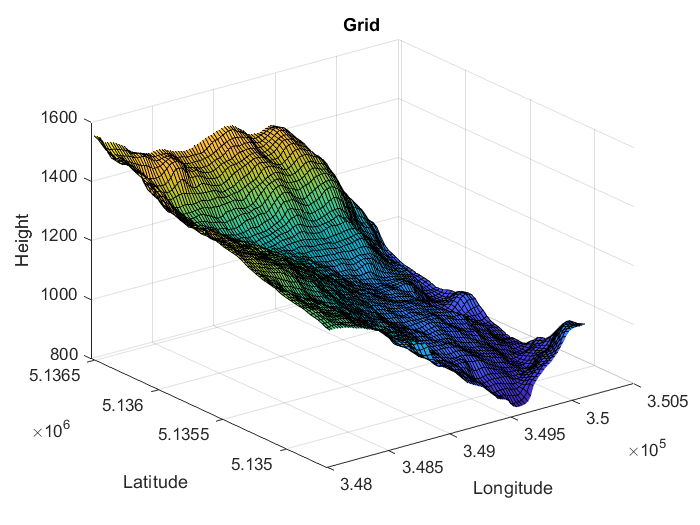

surf(X_mesh, Y_mesh, Z_mesh);
title('Grid');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');

if (rows*column > 3000 && rows*column <13000)
    l=0
    for i=1:2:column
        l=l+1;
        m=0;
        for j=1:2:rows
            m=m+1;
            xxx(m,l)=X_mesh(j,i);
            yyy(m,l)=Y_mesh(j,i);
            zzz(m,l)=Z_mesh(j,i);
            
        end
        
    end
    l
    m
    X_mesh=xxx
    Y_mesh=yyy
    Z_mesh=zzz
    rows=m
    column=l
    Xcell_size=(max(Grid.x)-min(Grid.x))/(column-1) % in meter
    Ycell_size=(max(Grid.y)-min(Grid.y))/(rows-1) % in meter
    szzx=2*szzx
    szzy=2*szzy
elseif (rows*column > 13000)
        l=0
    for i=1:3:column
        l=l+1;
        m=0;
        for j=1:3:rows
            m=m+1;
            xxx(m,l)=X_mesh(j,i);
            yyy(m,l)=Y_mesh(j,i);
            zzz(m,l)=Z_mesh(j,i);
            
        end
        
    end
    l
    m
    X_mesh=xxx
    Y_mesh=yyy
    Z_mesh=zzz
    rows=m
    column=l
    Xcell_size=(max(Grid.x)-min(Grid.x))/(column-1) % in meter
    Ycell_size=(max(Grid.y)-min(Grid.y))/(rows-1) % in meter
    szzx=3*szzx
    szzy=3*szzy
    
end

l =              0


l =          48.00


m =          31.00


X_mesh =      348025.52     348069.71     348113.89     348158.08     348202.27     348246.45     348290.64     348334.83     348379.01     348423.20     348467.39     348511.57     348555.76     348599.95     348644.13     348688.32     348732.51     348776.69     348820.88     348865.07     348909.25     348953.44     348997.63     349041.81     349086.00     349130.19     349174.38     349218.56     349262.75     349306.94     349351.12     349395.31     349439.50     349483.68     349527.87     349572.06     349616.24     349660.43     349704.62     349748.80     349792.99     349837.18     349881.36     349925.55     349969.74     350013.92     350058.11     350102.30
     348025.52     348069.71     348113.89     348158.08     348202.27     348246.45     348290.64     348334.83     348379.01     348423.20     348467.39     348511.57     348555.76     348599.95     348644.13     348688.32     348732.51     348776.69     348820.88     348865.07     348909.25     348953.44     34899

Y_mesh =     5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28    5136525.28
    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    5136464.20    513646

Z_mesh = 31×48 int16 matrix
   1551   1542   1519   1515   1507   1495   1478   1462   1453   1448   1442   1443   1445   1440   1431   1424   1420   1417   1421   1428   1437   1444   1449   1456   1462   1460   1453   1438   1420   1411   1410   1416   1423   1421   1407   1394   1361   1351   1337   1309   1278   1258   1243   1208   1175   1119   1090   1058
   1533   1504   1487   1483   1475   1469   1459   1456   1453   1439   1429   1432   1435   1430   1415   1396   1390   1391   1389   1393   1398   1408   1419   1429   1435   1433   1429   1423   1402   1397   1406   1419   1431   1428   1416   1387   1363   1347   1321   1292   1264   1244   1224   1180   1131   1108   1084   1055
   1519   1487   1483   1475   1452   1435   1411   1396   1392   1391   1404   1422   1429   1421   1397   1381   1380   1368   1362   1362   1372   1380   1384   1393   1401   1404   1404   1396   1380   1383   1397   1412   1418   1413   1401   1386   1356   1337   1312   1281   1258   1229   1

rows =          31.00


column =          48.00


Xcell_size =          44.19


Ycell_size =          61.08


szzx =          44.19


szzy =          61.08


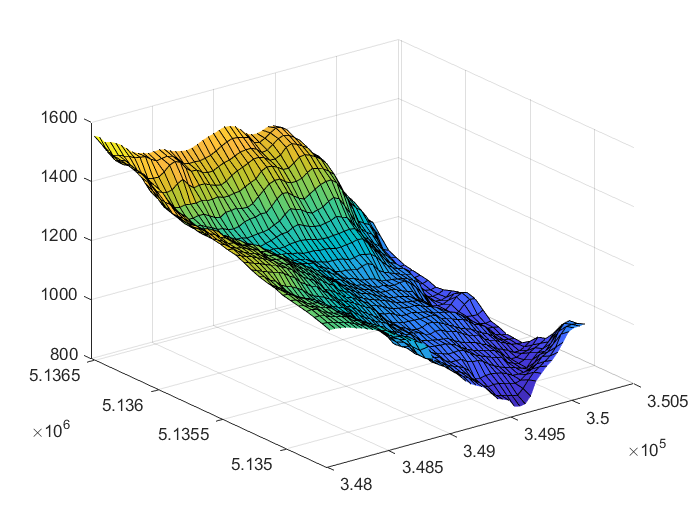

surf(X_mesh, Y_mesh, Z_mesh);


%Converting the grid into columns of x, y and z
x=zeros(1,column*rows);
y=zeros(1,column*rows);
z=zeros(1,column*rows);
l=1;
for i=1:column
    for j=1:rows
        x(l)=X_mesh(j,i);
        y(l)=Y_mesh(j,i);
        z(l)=Z_mesh(j,i);
        l=l+1;
   end
end
l

l =        1489.00


total.x=x;
total.y=y;
total.z=z

total = struct with fields:
    x: [1×1488 double]
    y: [1×1488 double]
    z: [1×1488 double]



%Importing the contour curve(Limits of the failur boundaries) as a KML file

crv=kml2struct(KML_file) 

crv = struct with fields:
       Geometry: 'Line'
           Name: 'frasse'
    Description: ''
            Lon: [235×1 double]
            Lat: [235×1 double]
    BoundingBox: [2×2 double]


x0=(crv.Lon)  

x0 =           7.03
          7.03
          7.03
          7.03
          7.03
          7.03
          7.03
          7.03
          7.03
          7.03


y0=(crv.Lat)

y0 =          46.36
         46.36
         46.36
         46.36
         46.36
         46.36
         46.36
         46.36
         46.36
         46.36



%crv =load('border.dat')
%x0=crv(:,1)
%y0=crv(:,2)
%Conversion of Lat Lon into UTM projection(converting the
% Geographic coordinate system into WGS 1984 UTM projection) and plotting
if x0<90
    [x0,y0,utmzone] = deg2utm(y0,x0);
end
contor.x=x0

contor = struct with fields:
    x: [235×1 double]


contor.y=y0

contor = struct with fields:
    x: [235×1 double]
    y: [235×1 double]


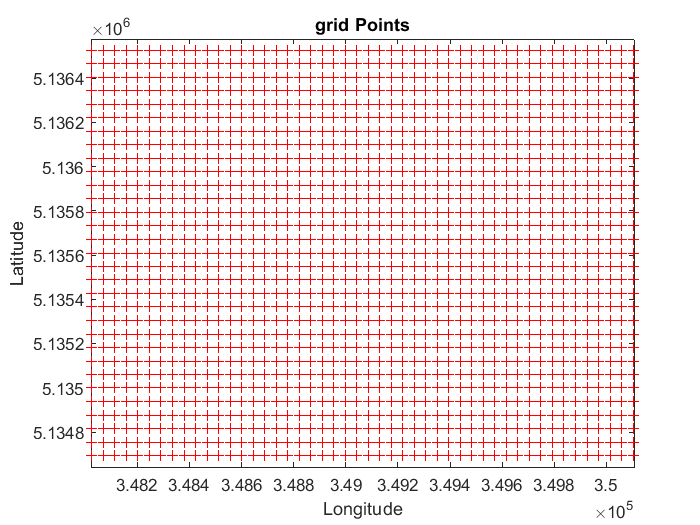


plot(total.x,total.y,'r+');
title('grid Points');
xlabel('Longitude');
ylabel("Latitude");
axis([(1-.00001)*min(total.x),(1+.00001)*max(total.x) (1-.00001)*min(total.y),(1+.00001)*max(total.y)])


rtm1=[1.001 0; 0 1.001];
m=[contor.x';contor.y']

m =      348097.27     348098.25     348099.40     348108.71     348128.58     348150.64     348166.93     348175.36     348186.32     348202.95     348214.25     348209.05     348194.64     348188.02     348191.13     348209.04     348246.56     348270.17     348310.10     348314.04     348330.55     348334.04     348373.74     348404.26     348419.35     348429.53     348444.80     348471.61     348501.91     348545.40     348562.59     348565.92     348597.56     348637.41     348674.05     348680.07     348696.71     348712.85     348731.32     348751.48     348753.02     348765.19     348769.32     348778.68     348778.99     348791.16     348798.15     348805.73     348837.37     348852.66
    5136177.36    5136189.64    5136201.62    5136225.45    5136249.22    5136271.97    5136281.71    5136297.31    5136332.64    5136366.22    5136412.40    5136428.49    5136471.80    5136512.13    5136557.98    5136566.20    5136566.26    5136560.72    5136523.62    5136519.50    5136511.40 

%((max(x0)+min(x0))/2)*0.1
uj=rtm1*m;
quary.Xt=uj(1,:)-((max(contor.x)+min(contor.x))/2)*0.001;
quary.Yt=uj(2,:)-((max(contor.y)+min(contor.y))/2)*0.001;
plot(contor.x,contor.y);
title('Landslide Contour');
xlabel('Longitude');
ylabel("Latitude");
hold on
plot(quary.Xt,quary.Yt)
plot(total.x,total.y,'r+')

%Extracting the points lying in side or on the contour boundaries
[in,on] = inpolygon(total.x,total.y,quary.Xt,quary.Yt)

in = 1×1488 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


on = 1×1488 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


in_boundary=numel(total.x(in))

in_boundary =         553.00


on_boundary=numel(total.x(on))

on_boundary =              0


quary.x=[total.x(in), total.x(on)];
quary.y=[total.y(in), total.x(on)];
quary.z=[total.z(in), total.x(on)]

quary = struct with fields:
    Xt: [1×235 double]
    Yt: [1×235 double]
     x: [1×553 double]
     y: [1×553 double]
     z: [1×553 double]



%Finding the line passing through heighest elevation point and lowest
%elevation point
[m,j]=max(quary.z)

m =        1507.00


j =          15.00


[mi,k]=min(quary.z)

mi =         828.00


k =         444.00


xma=quary.x(j)

xma =      348202.27


yma=quary.y(j)

yma =     5136525.28


zma=quary.z(j)

zma =        1507.00


xmi=quary.x(k)

xmi =      349572.06


ymi=quary.y(k)

ymi =     5134692.89


zmi=quary.z(k)

zmi =         828.00


if xma< xmi
   elevation_x=xma:xmi 
else
   elevation_x=xmi:xma 
end

elevation_x =      348202.27     348203.27     348204.27     348205.27     348206.27     348207.27     348208.27     348209.27     348210.27     348211.27     348212.27     348213.27     348214.27     348215.27     348216.27     348217.27     348218.27     348219.27     348220.27     348221.27     348222.27     348223.27     348224.27     348225.27     348226.27     348227.27     348228.27     348229.27     348230.27     348231.27     348232.27     348233.27     348234.27     348235.27     348236.27     348237.27     348238.27     348239.27     348240.27     348241.27     348242.27     348243.27     348244.27     348245.27     348246.27     348247.27     348248.27     348249.27     348250.27     348251.27



elevation_y=(elevation_x-xmi)*(yma-ymi)/(xma-xmi)+ymi

elevation_y =     5136525.28    5136523.94    5136522.60    5136521.26    5136519.93    5136518.59    5136517.25    5136515.91    5136514.57    5136513.24    5136511.90    5136510.56    5136509.22    5136507.89    5136506.55    5136505.21    5136503.87    5136502.53    5136501.20    5136499.86    5136498.52    5136497.18    5136495.85    5136494.51    5136493.17    5136491.83    5136490.50    5136489.16    5136487.82    5136486.48    5136485.14    5136483.81    5136482.47    5136481.13    5136479.79    5136478.46    5136477.12    5136475.78    5136474.44    5136473.11    5136471.77    5136470.43    5136469.09    5136467.75    5136466.42    5136465.08    5136463.74    5136462.40    5136461.07    5136459.73


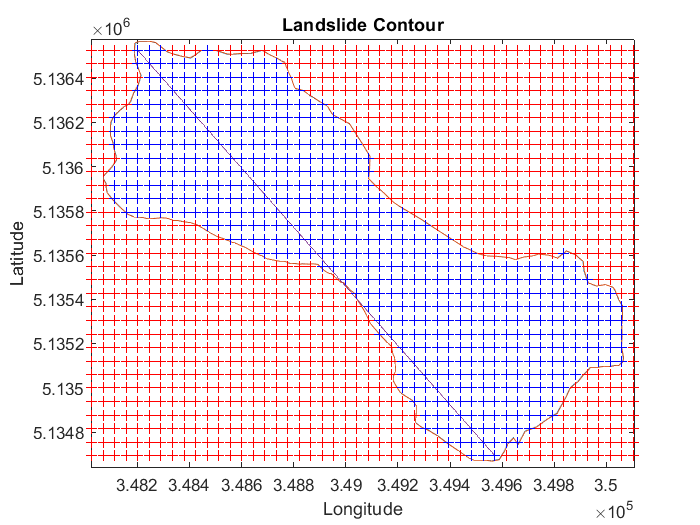

plot(elevation_x,elevation_y)
plot(quary.x,quary.y,'b+') % points inside and on the contour
axis([(1-.00001)*min(total.x),(1+.00001)*max(total.x) (1-.00001)*min(total.y),(1+.00001)*max(total.y)])
hold off


%Angle of rotation(coordinate transformation angle)
mm=(yma-ymi)/(xma-xmi)

mm =          -1.34


angle=atand(mm);
angle_from_yaxis=atand(1/mm)

angle_from_yaxis =         -36.78


rotation_angle=angle_from_yaxis  %rotation angle

rotation_angle =         -36.78



%Avarage slope of elevation
delta_z=zma-zmi

delta_z =         679.00


distance_zmax_zmin=sqrt((xma-xmi)*(xma-xmi)+(yma-ymi)*(yma-ymi))

distance_zmax_zmin =        2287.79


Avarage_slope=delta_z/distance_zmax_zmin

Avarage_slope =           0.30


slop_Angle=atand(Avarage_slope)

slop_Angle =          16.53



%Coordinate transformation of quary data 
rtn_matrix=[cosd(rotation_angle) -sind(rotation_angle); sind(rotation_angle) cosd(rotation_angle)];
mq=[quary.x;quary.y];
uj=rtn_matrix*mq;
quary.Xt=uj(1,:)

quary = struct with fields:
    Xt: [1×553 double]
    Yt: [1×235 double]
     x: [1×553 double]
     y: [1×553 double]
     z: [1×553 double]


quary.Yt=uj(2,:)

quary = struct with fields:
    Xt: [1×553 double]
    Yt: [1×553 double]
     x: [1×553 double]
     y: [1×553 double]
     z: [1×553 double]



[quary.Yts, sortIndex] = sort(quary.Yt,"descend");
quary.Xts = quary.Xt(sortIndex);
quary.Zts = quary.z(sortIndex);


%Coordinate tronsformation(rotating the axis in direction of cross-section line and elevation line) of imported curve and plotting

rtn_matrix=[cosd(rotation_angle) -sind(rotation_angle); sind(rotation_angle) cosd(rotation_angle)]

rtn_matrix =           0.80          0.60
         -0.60          0.80


mc=[contor.x';contor.y'];
Vfil=rtn_matrix*mc;
contor.xt=Vfil(1,:)

contor = struct with fields:
     x: [235×1 double]
     y: [235×1 double]
    xt: [1×235 double]


contor.yt=Vfil(2,:)

contor = struct with fields:
     x: [235×1 double]
     y: [235×1 double]
    xt: [1×235 double]
    yt: [1×235 double]



figure
plot(contor.xt,contor.yt);
hold on
title('Contour in Transformed coordinate');
xlabel('Longitude');
ylabel("Latitude");

%Elevation line rotation(Line joining the maximum and minimum elevation)
if xma< xmi
   elevation_x=xma:xmi 
else
   elevation_x=xmi:xma 
end

elevation_x =      348202.27     348203.27     348204.27     348205.27     348206.27     348207.27     348208.27     348209.27     348210.27     348211.27     348212.27     348213.27     348214.27     348215.27     348216.27     348217.27     348218.27     348219.27     348220.27     348221.27     348222.27     348223.27     348224.27     348225.27     348226.27     348227.27     348228.27     348229.27     348230.27     348231.27     348232.27     348233.27     348234.27     348235.27     348236.27     348237.27     348238.27     348239.27     348240.27     348241.27     348242.27     348243.27     348244.27     348245.27     348246.27     348247.27     348248.27     348249.27     348250.27     348251.27


elevation_y=(elevation_x-xmi)*(yma-ymi)/(xma-xmi)+ymi

elevation_y =     5136525.28    5136523.94    5136522.60    5136521.26    5136519.93    5136518.59    5136517.25    5136515.91    5136514.57    5136513.24    5136511.90    5136510.56    5136509.22    5136507.89    5136506.55    5136505.21    5136503.87    5136502.53    5136501.20    5136499.86    5136498.52    5136497.18    5136495.85    5136494.51    5136493.17    5136491.83    5136490.50    5136489.16    5136487.82    5136486.48    5136485.14    5136483.81    5136482.47    5136481.13    5136479.79    5136478.46    5136477.12    5136475.78    5136474.44    5136473.11    5136471.77    5136470.43    5136469.09    5136467.75    5136466.42    5136465.08    5136463.74    5136462.40    5136461.07    5136459.73



mcelv=[elevation_x;elevation_y];
Vfile=rtn_matrix*mcelv;
elevation_xt=Vfile(1,:)

elevation_xt =     3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32    3354337.32


elevation_yt=Vfile(2,:)

elevation_yt =     3905580.35    3905578.68    3905577.01    3905575.34    3905573.67    3905572.00    3905570.33    3905568.66    3905566.99    3905565.31    3905563.64    3905561.97    3905560.30    3905558.63    3905556.96    3905555.29    3905553.62    3905551.95    3905550.28    3905548.61    3905546.94    3905545.27    3905543.60    3905541.93    3905540.26    3905538.59    3905536.92    3905535.25    3905533.58    3905531.91    3905530.24    3905528.57    3905526.90    3905525.23    3905523.56    3905521.89    3905520.22    3905518.55    3905516.88    3905515.21    3905513.54    3905511.87    3905510.20    3905508.53    3905506.86    3905505.19    3905503.52    3905501.85    3905500.18    3905498.51


plot(elevation_xt,elevation_yt)
Xt_vertical=elevation_xt(1)

Xt_vertical =     3354337.32


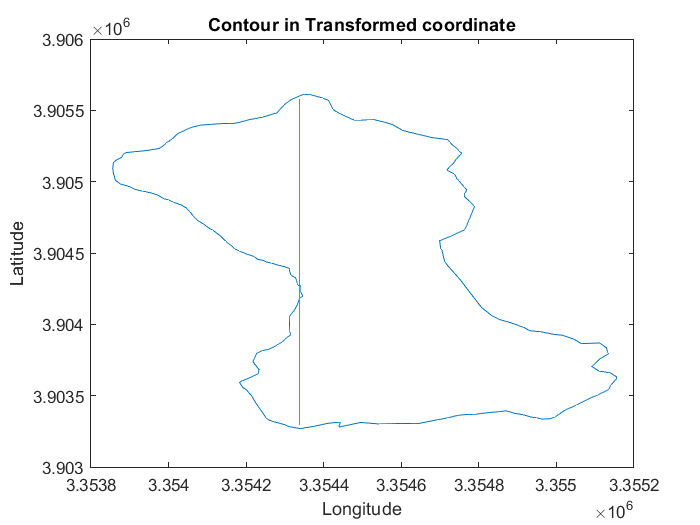

hold off

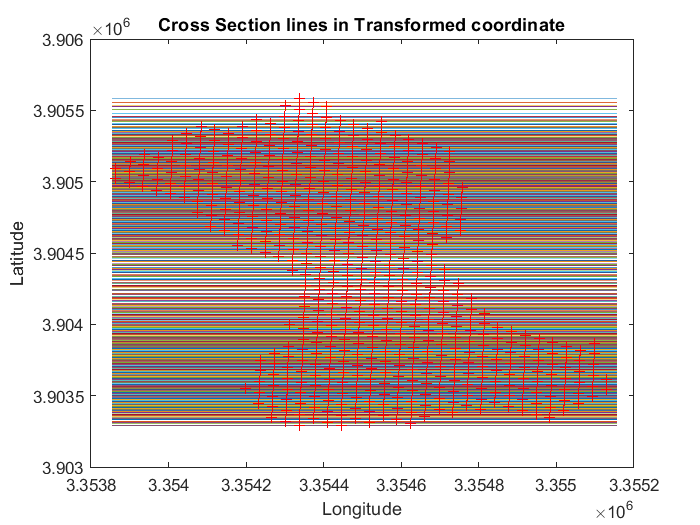


%Plotting of the crosssection lines
Yp=quary.Yts';
size(Yp);
cross_x=min(contor.xt)-2:1:max(contor.xt)+2;
cross_y=Yp+cross_x*0;
plot(cross_x,cross_y);
hold on
plot(quary.Xt,quary.Yt,'r+')
hold off
title('Cross Section lines in Transformed coordinate');
xlabel('Longitude');
ylabel("Latitude");

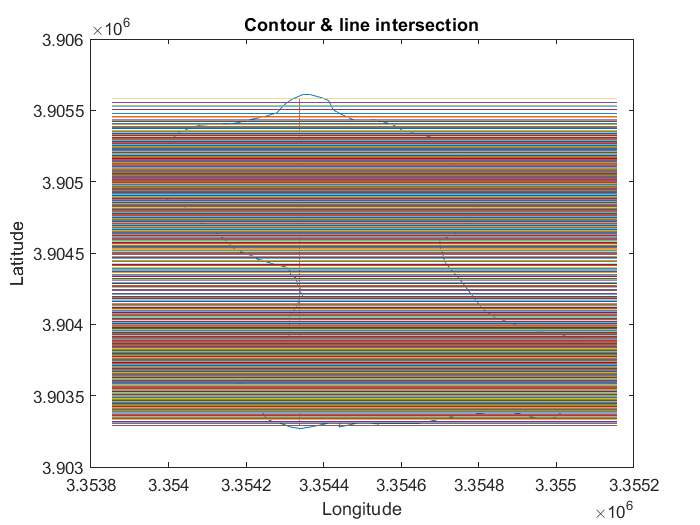




% Plotting the cross section and curve together in transformed coordinate
figure
plot(contor.xt,contor.yt);
hold on
plot(elevation_xt,elevation_yt)
plot(cross_x,cross_y);
title('Contour & line intersection');
xlabel('Longitude');
ylabel("Latitude");
hold off;

%Intersection of cross sections with curve and sorting(sorting the data
%based on y value for ease of calculation
Intersect_xy=zeros(length(quary.y),4)

Intersect_xy =              0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0
             0             0             0             0


for i=1:1:length(quary.y)
    Rt=cross_y(i,:);
    
   [xi,yi] = polyxpoly(contor.xt,contor.yt,cross_x,Rt);

    if length(xi)==2  
        Intersect_xy(i,1)=xi(1);
        Intersect_xy(i,3)=xi(2);
        Intersect_xy(i,2)=yi(1);
        Intersect_xy(i,4)=yi(2);
    elseif length(xi)==4
        if quary.Xts(i) >= xi(1) && quary.Xts(i) <= xi(2) 
           Intersect_xy(i,1)=xi(1);
           Intersect_xy(i,3)=xi(2);
           Intersect_xy(i,2)=yi(1);
           Intersect_xy(i,4)=yi(2);
        else
           Intersect_xy(i,1)=xi(3);
           Intersect_xy(i,3)=xi(4);
           Intersect_xy(i,2)=yi(3);
           Intersect_xy(i,4)=yi(4);
        end  
        
    elseif length(xi)==1
        Intersect_xy(i,1)=xi(1);
        Intersect_xy(i,3)=xi(1);
        Intersect_xy(i,2)=yi(1);
        Intersect_xy(i,4)=yi(1);
        
    elseif length(xi)==3
        if quary.Xts(i) >= xi(1) && quary.Xts(i) <=xi(2)
            Intersect_xy(i,1)=xi(1);
            Intersect_xy(i,3)=xi(2);
            Intersect_xy(i,2)=yi(1);
            Intersect_xy(i,4)=yi(2);
        else
            Intersect_xy(i,1)=xi(2);
            Intersect_xy(i,3)=xi(3);
            Intersect_xy(i,2)=yi(2);
            Intersect_xy(i,4)=yi(3);            
            
        end  
    elseif length(xi)==6
        if quary.Xts(i) >= xi(3) && quary.Xts(i) <=xi(4)
            Intersect_xy(i,1)=xi(3);
            Intersect_xy(i,3)=xi(4);
            Intersect_xy(i,2)=yi(3);
            Intersect_xy(i,4)=yi(4);            
        else
            Intersect_xy(i,1)=xi(5);
            Intersect_xy(i,3)=xi(6);
            Intersect_xy(i,2)=yi(5);
            Intersect_xy(i,4)=yi(6);           
        end
    else 
        Intersect_xy(i,1)=xi(1);
        Intersect_xy(i,3)=xi(2);
        Intersect_xy(i,2)=yi(1);
        Intersect_xy(i,4)=yi(2);       
    end
end

Intersect_xy

Intersect_xy =     3354319.76    3905580.35    3354402.63    3905580.35
    3354305.33    3905553.89    3354415.52    3905553.89
    3354295.66    3905531.43    3354419.61    3905531.43
    3354294.33    3905527.43    3354420.34    3905527.43
    3354286.87    3905504.97    3354425.35    3905504.97
    3354274.18    3905478.51    3354441.60    3905478.51
    3354246.89    3905456.05    3354457.93    3905456.05
    3354241.67    3905452.06    3354461.33    3905452.06
    3354206.44    3905433.58    3354477.33    3905433.58
    3354200.94    3905429.59    3354538.46    3905429.59


sect.Xlst=Intersect_xy(:,1);
sect.Ylst=Intersect_xy(:,2);
sect.Lt=[sect.Xlst,sect.Ylst]

sect = struct with fields:
    Xlst: [553×1 double]
    Ylst: [553×1 double]
      Lt: [553×2 double]




sect.Xrst=Intersect_xy(:,3);
sect.Yrst=Intersect_xy(:,4);
sect.Rt=[sect.Xrst,sect.Yrst]

sect = struct with fields:
    Xlst: [553×1 double]
    Ylst: [553×1 double]
      Lt: [553×2 double]
    Xrst: [553×1 double]
    Yrst: [553×1 double]
      Rt: [553×2 double]



sect.LRt=[sect.Lt;sect.Rt];

quary.xs=quary.x(sortIndex);
quary.ys=quary.y(sortIndex);
quary.zs=quary.z(sortIndex);

%Transforming into original coordinate system(Retaing the original
%coordinates after calculations)
rtn_matrix=[cosd(-rotation_angle) -sind(-rotation_angle); sind(-rotation_angle) cosd(-rotation_angle)]

rtn_matrix =           0.80         -0.60
          0.60          0.80


sect.L=rtn_matrix*sect.Lt';
sect.R=rtn_matrix*sect.Rt';
sect.LR=[sect.L sect.R]';
xy=[quary.xs' quary.ys']

xy =      348202.27    5136525.28
     348246.45    5136525.28
     348202.27    5136464.20
     348290.64    5136525.28
     348246.45    5136464.20
     348290.64    5136464.20
     348246.45    5136403.12
     348334.83    5136464.20
     348202.27    5136342.04
     348290.64    5136403.12


xycomb=[xy;sect.LR]

xycomb =      348202.27    5136525.28
     348246.45    5136525.28
     348202.27    5136464.20
     348290.64    5136525.28
     348246.45    5136464.20
     348290.64    5136464.20
     348246.45    5136403.12
     348334.83    5136464.20
     348202.27    5136342.04
     348290.64    5136403.12




% Calculating the Elevation(z values ) for Intersection Points. 

zi=[total.z';nan(length(sect.LR),1)]'

zi =        1551.00       1533.00       1519.00       1505.00       1505.00       1500.00       1498.00       1479.00       1460.00       1437.00       1409.00       1404.00       1399.00       1405.00       1405.00       1386.00       1381.00       1373.00       1368.00       1356.00       1342.00       1331.00       1323.00       1317.00       1305.00       1299.00       1293.00       1287.00       1279.00       1270.00       1260.00       1542.00       1504.00       1487.00       1485.00       1495.00       1486.00       1474.00       1464.00       1452.00       1423.00       1396.00       1386.00       1383.00       1388.00       1386.00       1377.00       1373.00       1371.00       1360.00


sect.LR(:,1)

ans =      348188.20
     348192.48
     348198.18
     348199.51
     348206.98
     348212.66
     348204.26
     348202.47
     348185.30
     348183.29


xi=[total.x';sect.LR(1:length(sect.LR),1)]'

xi =      348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348025.52     348069.71     348069.71     348069.71     348069.71     348069.71     348069.71     348069.71     348069.71     348069.71     348069.71     348069.71     348069.71     348069.71     348069.71     348069.71     348069.71     348069.71     348069.71     348069.71


yi=[total.y';sect.LR(1:length(sect.LR),2)]'

yi =     5136525.28    5136464.20    5136403.12    5136342.04    5136280.96    5136219.88    5136158.80    5136097.72    5136036.64    5135975.56    5135914.48    5135853.40    5135792.32    5135731.24    5135670.16    5135609.08    5135548.00    5135486.92    5135425.84    5135364.76    5135303.69    5135242.61    5135181.53    5135120.45    5135059.37    5134998.29    5134937.21    5134876.13    5134815.05    5134753.97    5134692.89    5136525.28    5136464.20    5136403.12    5136342.04    5136280.96    5136219.88    5136158.80    5136097.72    5136036.64    5135975.56    5135914.48    5135853.40    5135792.32    5135731.24    5135670.16    5135609.08    5135548.00    5135486.92    5135425.84



[zgrid,xgrid,ygrid] = gridfit(xi,yi,zi,min(xi):10:max(xi),min(yi):10:max(yi));


figure
surf(xgrid,ygrid,zgrid);
hold on
plot3(xi,yi,zi,'ro');
zgrid

zgrid =        1256.79       1256.93       1257.03       1257.04       1256.91       1256.64       1256.23       1255.74       1255.22       1254.71       1254.21       1253.67       1253.04       1252.23       1251.22       1249.98       1248.53       1246.94       1245.28       1243.62       1242.04       1240.61       1239.37       1238.30       1237.32       1236.32       1235.19       1233.85       1232.28       1230.51       1228.61       1226.70       1224.86       1223.15       1221.62       1220.27       1219.08       1217.99       1216.94       1215.81       1214.50       1212.90       1210.91       1208.45       1205.52       1202.20       1198.68       1195.21       1192.07       1189.44
       1258.33       1258.50       1258.62       1258.64       1258.51       1258.18       1257.66       1257.03       1256.37       1255.75       1255.21       1254.66       1254.03       1253.24       1252.21       1250.95       1249.53       1247.98       1246.35       1244.69       1243

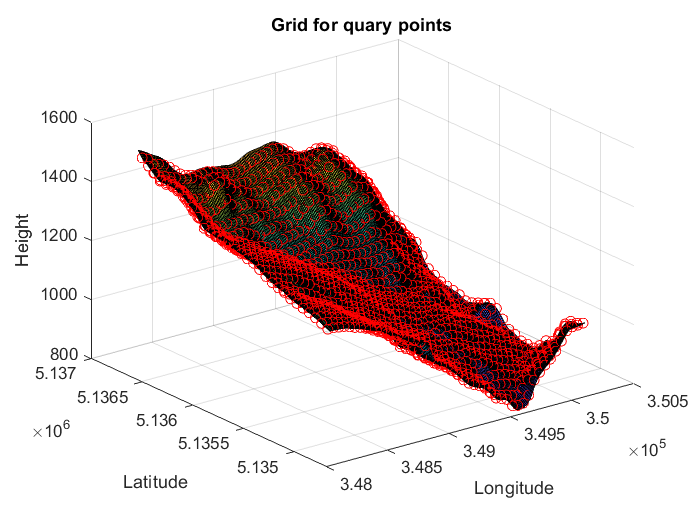

title('Grid for quary points');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');
hold off


%Left Profile z value calculation for intersection points
znanL = isnan(zi(1,1:length(zi)-length(sect.L)))

znanL = 1×2041 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


ZfilL = interp2(xgrid,ygrid,zgrid,xi(znanL),yi(znanL))

ZfilL =        1504.13       1486.96       1474.37       1472.48       1461.70       1448.67       1447.30       1447.99       1450.58       1449.19       1447.74       1446.27       1440.61       1460.31       1469.29       1474.27       1473.21       1471.96       1470.44       1468.94       1465.08       1463.66       1462.28       1460.98       1459.71       1457.79       1456.52       1454.94       1453.35       1451.83       1450.31       1447.90       1446.44       1444.97       1443.66       1442.46       1441.23       1440.45       1439.14       1437.78       1436.35       1434.79       1433.09       1431.09       1429.82       1427.70       1425.46       1423.20       1420.96       1418.81


voidL=isnan(ZfilL)

voidL = 1×553 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0



VfilL=find(voidL==1)


VfilL =

  1×0 empty double row vector




for a=1:1:length(VfilL)
    if VfilL(1,a)-3>0 && VfilL(1,a)+3<length(zi)
        if isnan(ZfilL(1,VfilL(1,a)-1)) && ~isnan(ZfilL(1,VfilL(1,a)+1))
            if isnan(ZfilL(1,VfilL(1,a)-2)) 
                ZfilL(1,VfilL(1,a))=(ZfilL(1,VfilL(1,a)-3)+ZfilL(1,VfilL(1,a)+1))/2;
            else, isnan(ZfilL(1,VfilL(1,a)-2)) 
                ZfilL(1,VfilL(1,a))=(ZfilL(1,VfilL(1,a)-2)+ZfilL(1,VfilL(1,a)+1))/2;
            end 
           
        elseif ~isnan(ZfilL(1,VfilL(1,a)-1)) &&  isnan(ZfilL(1,VfilL(1,a)+1))
            if isnan(ZfilL(1,VfilL(1,a)+2))
                ZfilL(1,VfilL(1,a))=(ZfilL(1,VfilL(1,a)-1)+ZfilL(1,VfilL(1,a)+3))/2;
            else
                ZfilL(1,VfilL(1,a))=(ZfilL(1,VfilL(1,a)-1)+ZfilL(1,VfilL(1,a)+2))/2; 
            end
        elseif isnan(ZfilL(1,VfilL(1,a)+1)) && isnan(ZfilL(1,VfilL(1,a)-1))
            if isnan(ZfilL(1,VfilL(1,a)+2)) && ~isnan(ZfilL(1,VfilL(1,a)-2))
                ZfilL(1,VfilL(1,a))=(ZfilL(1,VfilL(1,a)-2)+ZfilL(1,VfilL(1,a)+3))/2;
            elseif ~isnan(ZfilL(1,VfilL(1,a)+2)) && isnan(ZfilL(1,VfilL(1,a)-2))
                ZfilL(1,VfilL(1,a))=(ZfilL(1,VfilL(1,a)-3)+ZfilL(1,VfilL(1,a)+2))/2;
            end
        %elseif Vfil==length(Zfil)/2+1     
            %Zfil(1,Vfil(1,a))=(Zfil(1,Vfil(1,a)+1)+Zfil(1,Vfil(1,a)+2))/2;
       % elseif Vfil==length(Zfill)/2-1     
            %Zfil(1,Vfil(1,a))=(Zfil(1,Vfil(1,a)-11)+Zfil(1,Vfil(1,a)-2))/2;
        else
            
         ZfilL(1,VfilL(1,a))=(ZfilL(1,VfilL(1,a)-1)+ZfilL(1,VfilL(1,a)+1))/2;
         
        end 
    
    else
        if VfilL(1,a)-1==0
            ZfilL(1,VfilL(1,a))=(ZfilL(1,VfilL(1,a)+1)+ZfilL(1,VfilL(1,a)+2))/2;
        elseif VfilL(1,a)-1>0 && VfilL(1,a)-3<=0
            ZfilL(1,VfilL(1,a))=(ZfilL(1,VfilL(1,a)-1)+ZfilL(1,VfilL(1,a)+1))/2; 
        elseif VfilL(1,a)+1==length(zi)
            ZfilL(1,VfilR(1,a))=(ZfilL(1,VfilL(1,a)-1)+ZfilL(1,VfilL(1,a)-2))/2; 
        elseif VfilL(1,a)+1<length(zi) && VfilL(1,a)+3>=length(zi)
            ZfilL(1,VfilL(1,a))=(ZfilL(1,VfilL(1,a)-1)+ZfilL(1,VfilL(1,a)+1))/2;        
           
        end
    end
end
ZfilL

ZfilL =        1504.13       1486.96       1474.37       1472.48       1461.70       1448.67       1447.30       1447.99       1450.58       1449.19       1447.74       1446.27       1440.61       1460.31       1469.29       1474.27       1473.21       1471.96       1470.44       1468.94       1465.08       1463.66       1462.28       1460.98       1459.71       1457.79       1456.52       1454.94       1453.35       1451.83       1450.31       1447.90       1446.44       1444.97       1443.66       1442.46       1441.23       1440.45       1439.14       1437.78       1436.35       1434.79       1433.09       1431.09       1429.82       1427.70       1425.46       1423.20       1420.96       1418.81


check=isnan(ZfilL);
find(check==1)


ans =

  1×0 empty double row vector




%Right Profile z value calculation for intersection points
%zi=[total.z';nan(length(sect.R),1)]'
totl=[total.z';ZfilL';zi(1,length(zi)+1-length(sect.L):length(zi))']'

totl =        1551.00       1533.00       1519.00       1505.00       1505.00       1500.00       1498.00       1479.00       1460.00       1437.00       1409.00       1404.00       1399.00       1405.00       1405.00       1386.00       1381.00       1373.00       1368.00       1356.00       1342.00       1331.00       1323.00       1317.00       1305.00       1299.00       1293.00       1287.00       1279.00       1270.00       1260.00       1542.00       1504.00       1487.00       1485.00       1495.00       1486.00       1474.00       1464.00       1452.00       1423.00       1396.00       1386.00       1383.00       1388.00       1386.00       1377.00       1373.00       1371.00       1360.00


znanR = isnan(totl)

znanR = 1×2594 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0


ZfilR = interp2(xgrid,ygrid,zgrid,xi(znanR),yi(znanR))

ZfilR =            NaN       1487.12       1476.53       1474.97       1467.83       1462.15       1459.27       1458.54       1453.44       1443.40       1442.60       1442.03       1441.94       1442.21       1442.34       1442.10       1442.03       1441.96       1441.87       1441.78       1441.39       1441.34       1441.24       1440.92       1440.50       1439.35       1438.35       1437.19       1435.87       1434.37       1432.78       1430.05       1428.35       1426.79       1425.76       1425.35       1424.68       1423.63       1421.93       1420.20       1418.42       1416.63       1414.91       1413.17       1412.06       1410.38       1408.67       1407.15       1405.72       1404.30


voidR=isnan(ZfilR)

voidR = 1×553 logical array
   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0



VfilR=find(voidR==1)

VfilR =           1.00



for a=1:1:length(VfilR)
    if VfilR(1,a)-3>0 && VfilR(1,a)+3<length(zi) 
        if isnan(ZfilR(1,VfilR(1,a)-1)) && ~isnan(ZfilR(1,VfilR(1,a)+1))
            if isnan(ZfilR(1,VfilR(1,a)-2)) 
                ZfilR(1,VfilR(1,a))=(ZfilR(1,VfilR(1,a)-3)+ZfilR(1,VfilR(1,a)+1))/2;
            else, isnan(ZfilR(1,VfilR(1,a)-2)) 
                ZfilR(1,VfilR(1,a))=(ZfilR(1,VfilR(1,a)-2)+ZfilR(1,VfilR(1,a)+1))/2;
            end 
           
        elseif ~isnan(ZfilR(1,VfilR(1,a)-1)) &&  isnan(ZfilR(1,VfilR(1,a)+1))
            if isnan(ZfilR(1,VfilR(1,a)+2))
                ZfilR(1,VfilR(1,a))=(ZfilR(1,VfilR(1,a)-1)+ZfilR(1,VfilR(1,a)+3))/2;
            else
                ZfilR(1,VfilR(1,a))=(ZfilR(1,VfilR(1,a)-1)+ZfilR(1,VfilR(1,a)+2))/2; 
            end
        elseif isnan(ZfilR(1,VfilR(1,a)+1)) && isnan(ZfilR(1,VfilR(1,a)-1))
            if isnan(ZfilR(1,VfilR(1,a)+2)) && ~isnan(ZfilR(1,VfilR(1,a)-2))
                ZfilR(1,VfilR(1,a))=(ZfilR(1,VfilR(1,a)-2)+ZfilR(1,VfilR(1,a)+3))/2;
            elseif ~isnan(ZfilR(1,VfilR(1,a)+2)) && isnan(ZfilR(1,VfilR(1,a)-2))
                ZfilR(1,VfilR(1,a))=(ZfilR(1,VfilR(1,a)-3)+ZfilR(1,VfilR(1,a)+2))/2;
            end
        %elseif Vfil==length(Zfil)/2+1     
            %Zfil(1,Vfil(1,a))=(Zfil(1,Vfil(1,a)+1)+Zfil(1,Vfil(1,a)+2))/2;
       % elseif Vfil==length(Zfill)/2-1     
            %Zfil(1,Vfil(1,a))=(Zfil(1,Vfil(1,a)-11)+Zfil(1,Vfil(1,a)-2))/2;
        else
            
         ZfilR(1,VfilR(1,a))=(ZfilR(1,VfilR(1,a)-1)+ZfilR(1,VfilR(1,a)+1))/2;
        
        end   
    else
        if VfilR(1,a)-1==0
            ZfilR(1,VfilR(1,a))=(ZfilR(1,VfilR(1,a)+1)+ZfilR(1,VfilR(1,a)+2))/2;
        elseif VfilR(1,a)-1>0 && VfilR(1,a)-3<=0
            ZfilR(1,VfilR(1,a))=(ZfilR(1,VfilR(1,a)-1)+ZfilR(1,VfilR(1,a)+1))/2; 
        elseif VfilR(1,a)+1==length(zi)
            ZfilR(1,VfilR(1,a))=(ZfilR(1,VfilR(1,a)-1)+ZfilR(1,VfilR(1,a)-2))/2; 
        elseif VfilR(1,a)+1<length(zi) && VfilR(1,a)+3>=length(zi)
            ZfilR(1,VfilR(1,a))=(ZfilR(1,VfilR(1,a)-1)+ZfilR(1,VfilR(1,a)+1))/2;        
           
        end
    end
end
ZfilR

ZfilR =        1481.82       1487.12       1476.53       1474.97       1467.83       1462.15       1459.27       1458.54       1453.44       1443.40       1442.60       1442.03       1441.94       1442.21       1442.34       1442.10       1442.03       1441.96       1441.87       1441.78       1441.39       1441.34       1441.24       1440.92       1440.50       1439.35       1438.35       1437.19       1435.87       1434.37       1432.78       1430.05       1428.35       1426.79       1425.76       1425.35       1424.68       1423.63       1421.93       1420.20       1418.42       1416.63       1414.91       1413.17       1412.06       1410.38       1408.67       1407.15       1405.72       1404.30


check=isnan(ZfilR);
Ck=find(check==1)


Ck =

  1×0 empty double row vector




%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%Combining the calculated elevation data ate intersected points into a
%single matrix for further proccessing

sect.Zl=ZfilL'

sect = struct with fields:
    Xlst: [553×1 double]
    Ylst: [553×1 double]
      Lt: [553×2 double]
    Xrst: [553×1 double]
    Yrst: [553×1 double]
      Rt: [553×2 double]
     LRt: [1106×2 double]
       L: [2×553 double]
       R: [2×553 double]
      LR: [1106×2 double]
      Zl: [553×1 double]


sect.Zr=ZfilR'

sect = struct with fields:
    Xlst: [553×1 double]
    Ylst: [553×1 double]
      Lt: [553×2 double]
    Xrst: [553×1 double]
    Yrst: [553×1 double]
      Rt: [553×2 double]
     LRt: [1106×2 double]
       L: [2×553 double]
       R: [2×553 double]
      LR: [1106×2 double]
      Zl: [553×1 double]
      Zr: [553×1 double]


sect.Zlr=[sect.Zl;sect.Zr];


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% 3 Different approches have been used to get the cross-section angles with
% failure surface for each cross-section lines, so that they can be used in
% calculation of elevation using spline method in the next step.

%Calculation of cross-section angles with failure surface for the right profile 

%Right profile-Right portion of the failure surface divided by the
% elevation line
% Elevation line-The line joining the max elevation to min within the contour boundaries


% For Right profile
Intersect_xy;
sect.Xrst=Intersect_xy(:,3);
sect.Yrst=Intersect_xy(:,4);
sect.Rt=[sect.Xrst,sect.Yrst]

sect = struct with fields:
    Xlst: [553×1 double]
    Ylst: [553×1 double]
      Lt: [553×2 double]
    Xrst: [553×1 double]
    Yrst: [553×1 double]
      Rt: [553×2 double]
     LRt: [1106×2 double]
       L: [2×553 double]
       R: [2×553 double]
      LR: [1106×2 double]
      Zl: [553×1 double]
      Zr: [553×1 double]
     Zlr: [1106×1 double]



sect.LRt=[sect.Lt;sect.Rt];

len=length(sect.Lt)

len =         553.00


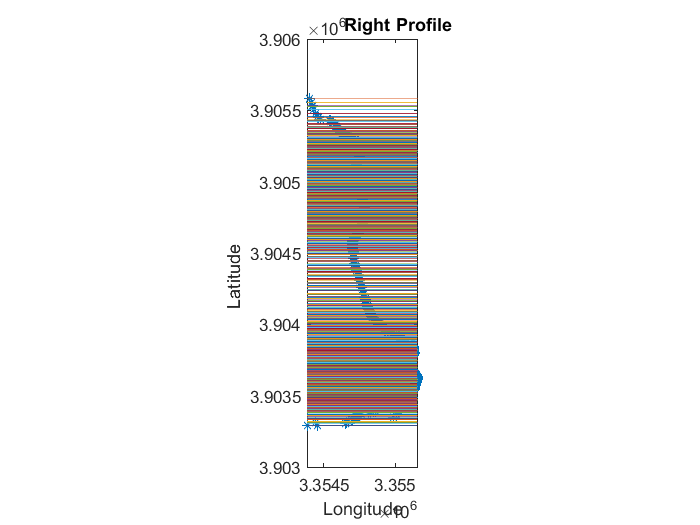

Csr =          23.00
         23.00
         23.00
         23.00
         23.00
         23.00
         23.00
         23.00
         23.00
         23.00


rrx=sect.Rt(:,1)';
rry=sect.Rt(:,2)';
plot(rrx,rry,'*');

daspect([1 1 1])
%axis square
hold on 
Yrn=rry';
size(Yrn);
xre=min(rrx)-2:1:max(rrx)+2;
cross_y=Yrn+xre*0;
plot(xre,cross_y);

xlabel('Longitude');
ylabel(" Latitude          ");
%Method-1 Right Profile
if Method==1
    % The true angle between cross section line and falure plane Method-1
    title('              Right Profile');
    hold off
    Csr=zeros(1,len)'; 
    Right_Dip_angle;
    for i=1:len
        Csr(i)=Right_Dip_angle;
    end
    Csr
%Method-2 Right Profile    
elseif(Method==2) 
    title('             Right Profile');
    hold off
   % Rgt.top_dip= str2double(Right_profile{1})
   % Rgt.top_strik= str2double(Right_profile{2})
   % Rgt.botm_dip= str2double(Right_profile{3})
   % Rgt.botm_strik= str2double(Right_profile{4})
    
    % Right Profile Dip angle Method-2
    sumr=0;
    for i=1:1:len
        sumr=1/abs(abs(sect.Xrst(i))-abs(Xt_vertical))+sumr;
    end
    Weightr=abs(sumr);
    kr=Rgt.top_dip;
    Dr=zeros(1,len)';
    Dr(1,1)=Rgt.top_dip;
    
    for i=1:1:len-1
        dip=kr-(abs(1/(abs(sect.Xrst(i))-abs(Xt_vertical)))/Weightr)*(Rgt.top_dip-Rgt.botm_dip);
        kr=dip;
        Dr(i+1,1)=dip;
    end
    Dr    
    
    %Right Profile strik angle Method-2
    Sr=zeros(1,len)';
    Sr(1,1)=Rgt.top_strik;
    sumr=0;
    for i=1:1:len
        sumr=1/abs(abs(sect.Xrst(i))-abs(Xt_vertical))+sumr;
    end
    lr=Rgt.top_strik;
    Weightr=abs(sumr);
    for i=1:1:len-1
        por=lr+(abs(1/(abs(sect.Xrst(i))-abs(Xt_vertical)))/Weightr)*(Rgt.botm_strik-Rgt.top_strik);
        lr=por;
        Sr(i+1,1)=por;
    end
    Sr
    
    % The true angle between cross section line and falure plane Method-2
    Csr=zeros(1,len)';    
    for a=1:1:len
       uu=tand(Dr(a,1))*cosd(180-Sr(a,1));
       fd=atand(uu);
       Csr(a,1)=fd;
    end 
    Csr
%Method-3 Right Profile    
elseif(Method==3)
    title('Intersection of normals from the approximated arc');

   % Rgt.top_dip= str2double(Right_profile{1})
   % Rgt.top_strik= str2double(Right_profile{2})
   % Rgt.botm_dip= str2double(Right_profile{3})
   % Rgt.botm_strik= str2double(Right_profile{4})
    
    normr1=Rgt.top_strik-90
    normr2=Rgt.botm_strik-90
    
    slopr1=tand(90-normr1);
    slopr2=tand(90-normr2);
    
     xrm=(sect.Yrst(1,1)+slopr2*sect.Xrst(length(sect.Xrst),1)- ...
        sect.Yrst(length(sect.Yrst),1)-slopr1*sect.Xrst(1,1))/(slopr2-slopr1)
    yrm=(slopr2*(sect.Yrst(1,1)+slopr1*sect.Xrst(length(sect.Xrst),1)) ...
        -slopr1*(sect.Yrst(length(sect.Yrst),1)+slopr2*sect.Xrst(1,1)))/(slopr2-slopr1)
    %[xrm,yrm] = polyxpoly(xr1,yr1,xr1,yr2)   
    
    if(sect.LRt(1,1)<0)
        eer1=xrm*1.00005;
        eer2=max(sect.LRt(:,1))*.99990;
    else
        eer1=xrm*.99995;
        eer2=max(sect.LRt(:,1))*1.00009;        
    end

    xr1=eer1:1:eer2;
    
    yr1=sect.Yrst(1,1)+(xr1-sect.Xrst(1,1))*slopr1;
    yr2=sect.Yrst(length(sect.Yrst),1)+(xr1-sect.Xrst(length(sect.Xrst),1))*slopr2;

    
    
    plot(xr1,yr1,xr1,yr2)
    axis([eer1 eer2 min(sect.LRt(:,2)) max(sect.LRt(:,2))])
    hold on
    plot(xrm, yrm,'*')
    hold off
    
    %Right Profile Dip angle Method-3
    mr=(Rgt.botm_dip-Rgt.top_dip)/(Rgt.botm_strik-Rgt.top_strik);
    kr=Rgt.top_dip;
    Dr=zeros(1,len)';
    Dr(1,1)=Rgt.top_dip;
    
    for a=1:1:len-1
        
        i=sect.Xrst(a)-sect.Xrst(a+1);
        j=sect.Yrst(a)-sect.Yrst(a+1);
        hh=sqrt(i*i+j*j);
        ii=sect.Xrst(a)-xrm;
        jj=sect.Yrst(a)-yrm;
        ln=sqrt(ii*ii+jj*jj);
        Sr=hh/ln;
        do=(180/pi)*Sr;
        gd=atand(hh/ln);
        dip=gd*mr+kr;
        kr=dip;
        Dr(a+1,1)=dip;
    end
    Dr

   %Right Profile strike angle Method-3
    Sr=zeros(1,len)';
    lr=Rgt.top_strik;
    Sr(1,1)=Rgt.top_strik;
    
    for a=1:1:len-1 
        i=sect.Xrst(a)-sect.Xrst(a+1);
        j=sect.Yrst(a)-sect.Yrst(a+1);
        hh=sqrt(i*i+j*j);
        ii=sect.Xrst(a)-xrm;
        jj=sect.Yrst(a)-yrm;
        ln=sqrt(ii*ii+jj*jj);
        u=hh/ln;
        gd=atand(u);
        strik=gd+lr;
        lr=strik;
        Sr(a+1,1)=strik;
    end
    Sr
    
    % The true angle between cross section line and falure plane Method-3
    Csr=zeros(1,len)';
    
    for a=1:1:len
       uu=tand(Dr(a,1))*cosd(180-Sr(a,1));
       fd=atand(uu);
       Csr(a,1)=fd;
    end 
    Csr

end    

%Calculation of cross-section angles with failure surface for the Left profile 
%Left profile-Right portion of the failure surface divided by the elevation line
% Elevation line- The line joining the max elevation to min within the contour boundaries


%Left profile

Intersect_xy;
sect.Xlst=Intersect_xy(:,1);
sect.Ylst=Intersect_xy(:,2);
sect.Lt=[sect.Xlst,sect.Ylst];

len=length(sect.Lt)

len =         553.00


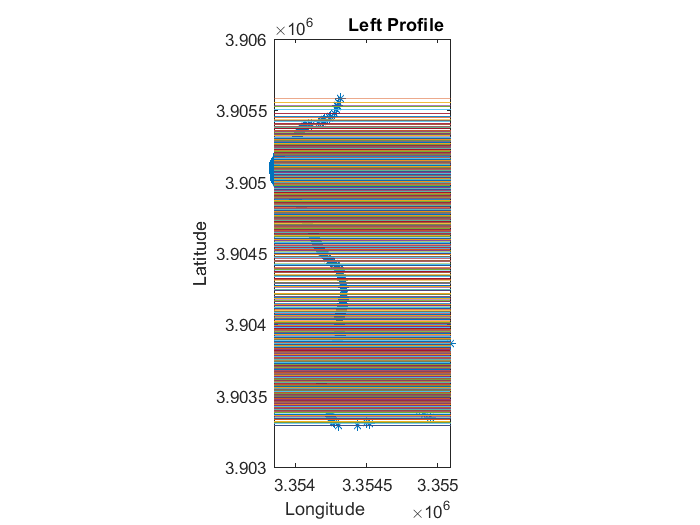

Csl =          23.00
         23.00
         23.00
         23.00
         23.00
         23.00
         23.00
         23.00
         23.00
         23.00


lld=sect.Lt(:,1)';
lle=sect.Lt(:,2)';
plot(lld,lle,'*')
hold on

daspect([1 1 1]);
%axis square

Yln=lle';
size(Yln);
xle=min(lld)-4:1:max(lld)+2;
Ylfn=Yln+xle*0;
plot(xle,Ylfn);

xlabel('Longitude               ');
ylabel("Latitude");

%Method-1 Left Profile
% The true angle between cross section line and plane Method-1

if (Method==1)
    hold off
    title('             Left Profile');
    Csl=zeros(1,len)';
    Left_Dip_angle;
    for i=1:len
        Csl(i)=Left_Dip_angle;
    end
    Csl
%Method-2 Left Profile 

elseif(Method==2)
    title('              Left Profile');
    hold off
   % Lft.top_dip= str2double(Left_profile{1})
   % Lft.top_strik= str2double(Left_profile{2})
   % Lft.botm_dip= str2double(Left_profile{3})
   % Lft.botm_strik= str2double(Left_profile{4})
    
    suml=0;
    for i=1:1:len
        suml=1/abs(abs(sect.Xlst(i))-abs(Xt_vertical))+suml;
    end
    %Left profile Strike angle Method-2
    Weightl=abs(suml);
    kl=Lft.top_dip;
    Dl=zeros(1,len)';
    Dl(1,1)=Lft.top_dip;
    
    for i=1:1:len-1
        dip=kl-(abs(1/(abs(sect.Xrst(i))-abs(Xt_vertical)))/Weightl)*(Lft.top_dip-Lft.botm_dip);
        kl=dip;
        Dl(i+1,1)=dip;
    end
    Dl   
    
    %Left profile Strike angle Method-2  
    Sl=zeros(1,len)'; 
    Sl(1,1)=Lft.top_strik;
    suml=0;
    for i=1:1:len
        suml=1/abs(abs(Xt_vertical)-abs(sect.Xlst(i)))+suml;
    end
    ll=Lft.top_strik;
    Weightl=abs(suml);
    for i=1:1:len
        po=ll-(abs(1/(abs(Xt_vertical)-abs(sect.Xlst(i))))/Weightl)*(Lft.top_strik-Lft.botm_strik);
        ll=po;
        Sl(i+1,1)=po;
    end
    Sl
    
    % The true angle between cross section line and plane Method-2
    Csl=zeros(1,len)';
    
    for a=1:1:len
        
       uu=tand(Dl(a,1))*cosd(180-Sl(a,1));
       fd=atand(uu);
       Csl(a,1)=fd;
    end 
    
    Csl
% Method-3 Left Profile  

elseif (Method==3)
    title('Intersection of normals from the approximated arc');
   % Lft.top_dip= str2double(Left_profile{1});
   % Lft.top_strik= str2double(Left_profile{2});
   % Lft.botm_dip= str2double(Left_profile{3});
   % Lft.botm_strik= str2double(Left_profile{4})
    
    norml1=Lft.top_strik-90
    norml2=Lft.botm_strik-90
    
    slopl1=tand(90-norml1);
    slopl2=tand(90-norml2);
    
    xlm=(sect.Ylst(1,1)+slopl2*sect.Xlst(length(sect.Xlst),1)- ...
        sect.Ylst(length(sect.Ylst),1)-slopl1*sect.Xlst(1,1))/(slopl2-slopl1)
    ylm=(slopl2*(sect.Ylst(1,1)+slopl1*sect.Xlst(length(sect.Xlst),1)) ...
        -slopl1*(sect.Ylst(length(sect.Ylst),1)+slopl2*sect.Xlst(1,1)))/(slopl2-slopl1)    
    
    if(sect.LRt(1,1)<0)
        eel1=min(sect.LRt(:,1))*1.00005;
        eel2=xlm*.99995;
    else
        eel1=min(sect.LRt(:,1))*.99995;
        eel2=xlm*1.00005;        
    end
    xl1=eel1:eel2;
    
    yl1=sect.Ylst(1,1)+(xl1-sect.Xlst(1,1))*slopl1;
    yl2=sect.Ylst(length(sect.Ylst),1)+(xl1-sect.Xlst(length(sect.Xlst),1))*slopl2;

    
    %[xlm,ylm] = polyxpoly(xl1,yl1,xl1,yl2)
    plot(xl1,yl1,xl1,yl2)
    hold on
    axis([eel1 eel2 min(sect.LRt(:,2)) max(sect.LRt(:,2))]);
    
    plot(xlm, ylm,'*');
    hold off  
    
    %Left profile Strike angle Method-3
    ml=(Lft.botm_dip-Lft.top_dip)/(Lft.botm_strik-Lft.top_strik);
    kl=Lft.top_dip;
    Dl=zeros(1,len)';
    Dl(1,1)=Lft.top_dip;
    
    for a=1:1:len-1     
        i=sect.Xlst(a)-sect.Xlst(a+1);
        j=sect.Ylst(a)-sect.Ylst(a+1);
        hh=sqrt(i*i+j*j);
        ii=sect.Xlst(a)-xlm;
        jj=sect.Ylst(a)-ylm;
        ln=sqrt(ii*ii+jj*jj);
        Sr=hh/ln;
        do=(180/pi)*Sr;
        gdl=atand(hh/ln);
        dipl=-gdl*ml+kl;
        kl=dipl;
        Dl(a+1,1)=dipl;
    end
    Dl

    %Left Profile strike angle Method-3
    Sl=zeros(1,len)';
    lr=Lft.top_strik;
    Sl(1,1)=Lft.top_strik;
    
    for a=1:1:len-1
        i=sect.Xlst(a)-sect.Xlst(a+1);
        j=sect.Ylst(a)-sect.Ylst(a+1);
        hh=sqrt(i*i+j*j);
        ii=sect.Xlst(a)-xlm;
        jj=sect.Ylst(a)-ylm;
        ln=sqrt(ii*ii+jj*jj);
        u=hh/ln;
        gdl=atand(u);
        strik=-gdl+lr;
        lr=strik;
        Sl(a+1,1)=strik;
    end
    Sl
    % The true angle between cross section line and plane Method-3
    Csl=zeros(1,len)';
    
    for a=1:1:len
        
       uu=tand(Dl(a,1))*cosd(180-Sl(a,1));
       fd=atand(uu);
       Csl(a,1)=fd;
    end 
    Csl

end


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
sect.Zl=ZfilL'

sect = struct with fields:
    Xlst: [553×1 double]
    Ylst: [553×1 double]
      Lt: [553×2 double]
    Xrst: [553×1 double]
    Yrst: [553×1 double]
      Rt: [553×2 double]
     LRt: [1106×2 double]
       L: [2×553 double]
       R: [2×553 double]
      LR: [1106×2 double]
      Zl: [553×1 double]
      Zr: [553×1 double]
     Zlr: [1106×1 double]


sect.Zr=ZfilR'

sect = struct with fields:
    Xlst: [553×1 double]
    Ylst: [553×1 double]
      Lt: [553×2 double]
    Xrst: [553×1 double]
    Yrst: [553×1 double]
      Rt: [553×2 double]
     LRt: [1106×2 double]
       L: [2×553 double]
       R: [2×553 double]
      LR: [1106×2 double]
      Zl: [553×1 double]
      Zr: [553×1 double]
     Zlr: [1106×1 double]


sect.Zlr=[sect.Zl;sect.Zr];

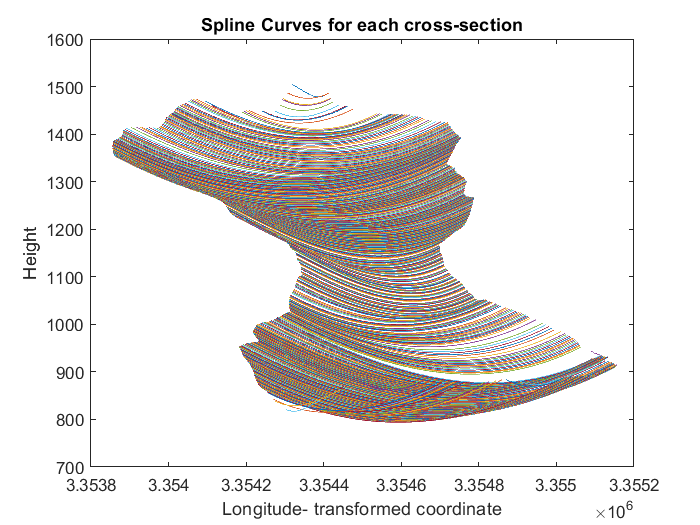


%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%code for getting the Z values using spline and Poly3 functions.

zout=zeros(length(quary.y),1);
for a=1:1:length(quary.y)
    x=Intersect_xy(a,1):.01:Intersect_xy(a,3);
    Spm.Y_1	= sect.Zl(a,1);
    Spm.Y_2	=sect.Zr(a,1); 
    Spm.X_1	=sect.Xlst(a,1);
    Spm.X_2	=sect.Xrst(a);
    Spm.angle_left=-Csl(a,1)+180;
    Spm.angle_right=-Csr(a,1);
    Spm.slope_left=tand(Spm.angle_left)*(Spm.X_2-Spm.X_1);
    Spm.slope_right=tand(-Spm.angle_right)*(Spm.X_2-Spm.X_1);
    Spm.D_1	=Spm.slope_left;
    Spm.D_2	=Spm.slope_right; 
    Spm.shift=0;
    param=spline_param_new(Spm);
    b=poly3n(param,quary.Xts(a));
    zout(a,1)=b;
    spl=poly3n(param,x);
    plot(x,spl)  %Ploting the spline curve for each point
    hold on
    
end
hold off
title('Spline Curves for each cross-section');
xlabel('Longitude- transformed coordinate');
ylabel("Height");

       
%Elevation for each grid point- will be same for transformed
%original-coordinate system(Z value remains same -either in original
%coordinate system or in transformed coordinate system

zout;
bnew=zout'

bnew =        1495.67       1475.96       1472.31       1470.22       1450.00       1439.75       1432.38       1439.55       1442.34       1412.87       1413.01       1441.78       1409.22       1401.28       1411.52       1468.84       1427.84       1403.41       1398.12       1413.87       1436.02       1404.91       1390.36       1393.33       1413.90       1448.94       1410.51       1386.38       1377.01       1382.79       1404.00       1421.58       1388.22       1367.82       1360.83       1367.59       1388.65       1437.85       1396.74       1367.91       1351.81       1348.97       1360.01       1385.40       1408.08       1371.43       1347.02       1335.59       1337.62       1353.43


zcomb=[zout;sect.Zlr]';
zcombd=[quary.zs';sect.Zlr]';

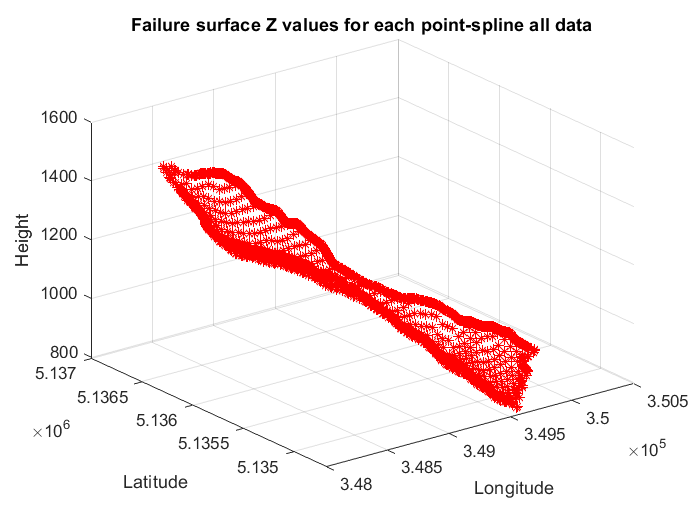

%Plotting the original surface height and failure surface in original coordinate system
figure
plot3((xycomb(:,1))',(xycomb(:,2))',zcomb,'*',"Color",'r')
title('Failure surface Z values for each point-spline all data');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');
grid on;

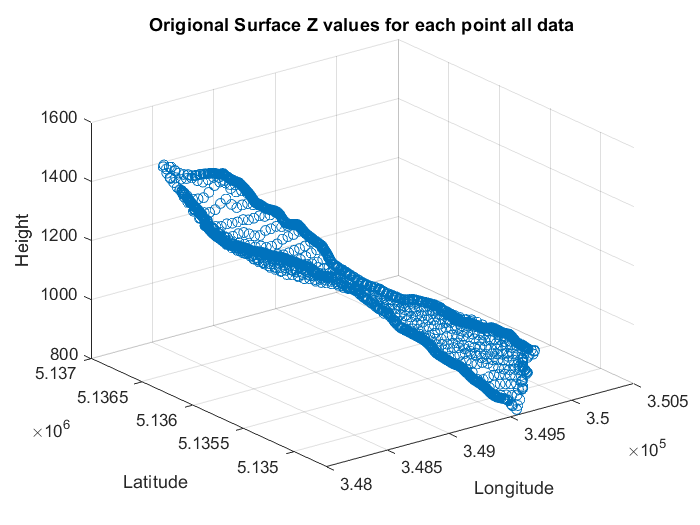


plot3((xycomb(:,1))',(xycomb(:,2))',zcombd,'o')
title('Origional Surface Z values for each point all data');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');
grid on;

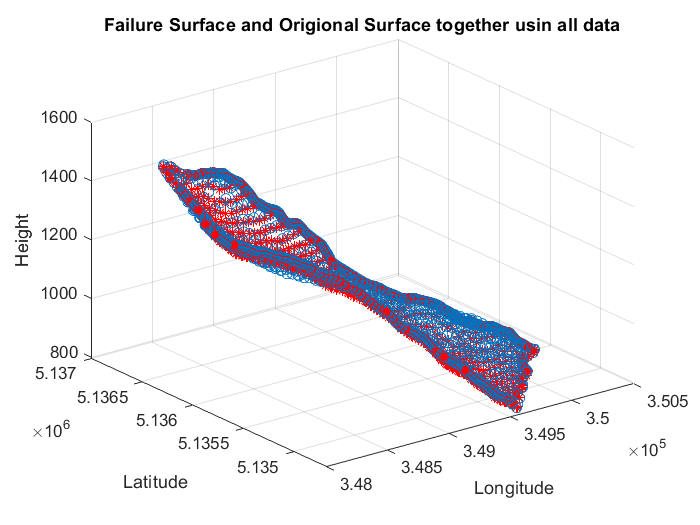


figure
plot3((xycomb(:,1))',(xycomb(:,2))',zcombd,'o');
hold on 
plot3((xycomb(:,1))',(xycomb(:,2))',zcomb,'*',"Color",'r')
hold off
title('Failure Surface and Origional Surface together usin all data');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');
grid on;

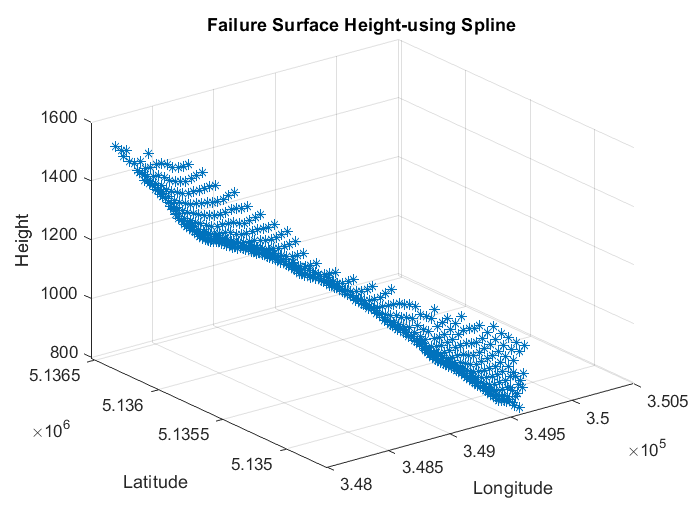


% Plotting the height in Original coordinate system
figure
plot3(quary.xs,quary.ys,bnew,'*');
title('Failure Surface Height-using Spline');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');
grid on;

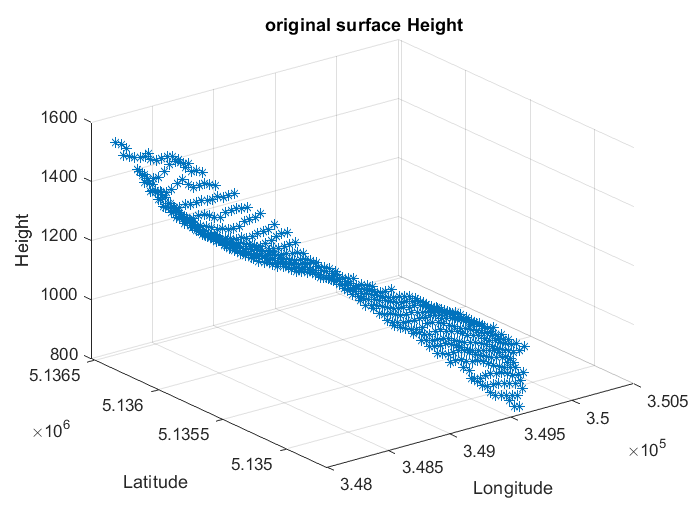


plot3(quary.xs,quary.ys,quary.zs,'*'); %surface height 
title(' original surface Height');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');
grid on;

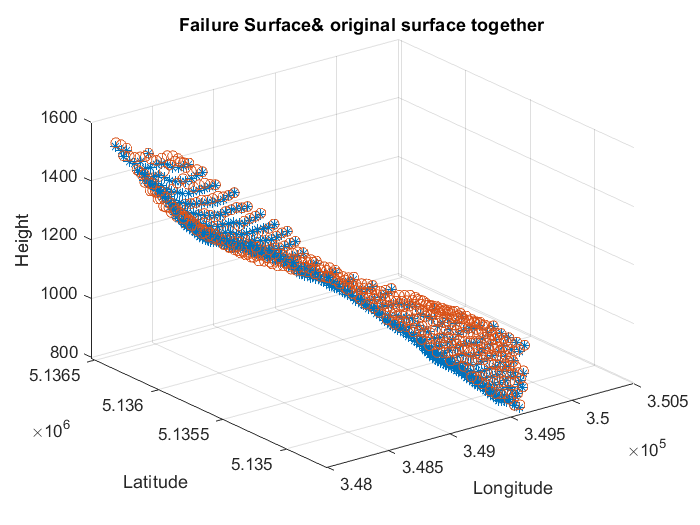


figure
plot3(quary.xs,quary.ys,bnew,'*'); %failure surface height-using spline
title('Failure Surface& original surface together');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');
hold on ;
grid on
plot3(quary.xs,quary.ys,quary.zs,'o');
hold off;


% Failure surface ploting with original grid and original Coordinate system

Grid.xv = linspace(min((xycomb(:,1))), max((xycomb(:,1))),column );
Grid.yv = linspace(min((xycomb(:,2))), max((xycomb(:,2))),rows);
[Grid.Xo1,Grid.Yo1] = meshgrid(Grid.xv, Grid.yv);
Grid.Zo1 = griddata((xycomb(:,1))',(xycomb(:,2))',zcombd,Grid.Xo1,Grid.Yo1)

Grid = struct with fields:
      x: [1×95 double]
      y: [1×61 double]
     xv: [1×48 double]
     yv: [1×31 double]
    Xo1: [31×48 double]
    Yo1: [31×48 double]
    Zo1: [31×48 double]


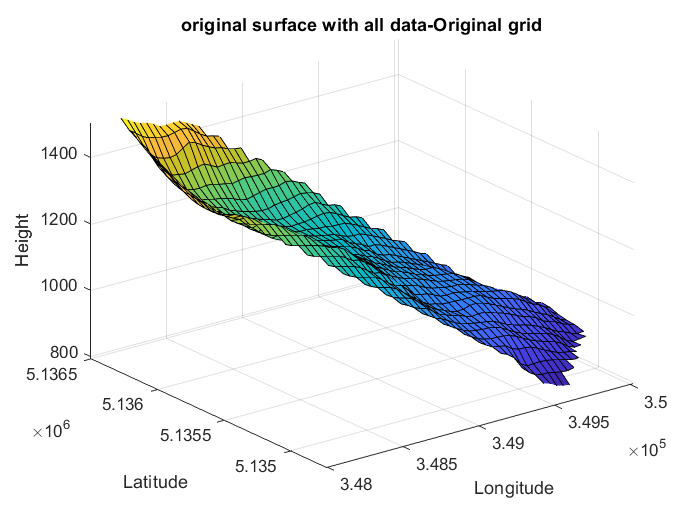


surf(Grid.Xo1, Grid.Yo1, Grid.Zo1);
title('original surface with all data-Original grid');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');
grid on
set(gca, 'ZLim',[min(zout) max(quary.Zts)])


%Failure surface with all data 

Grid.xv = linspace(min((xycomb(:,1))), max((xycomb(:,1))),column );
Grid.yv = linspace(min((xycomb(:,2))), max((xycomb(:,2))),rows);
[Grid.Xf1,Grid.Yf1] = meshgrid(Grid.xv, Grid.yv);
Grid.Zf1 = griddata((xycomb(:,1))',(xycomb(:,2))',zcomb,Grid.Xf1,Grid.Yf1)

Grid = struct with fields:
      x: [1×95 double]
      y: [1×61 double]
     xv: [1×48 double]
     yv: [1×31 double]
    Xo1: [31×48 double]
    Yo1: [31×48 double]
    Zo1: [31×48 double]
    Xf1: [31×48 double]
    Yf1: [31×48 double]
    Zf1: [31×48 double]


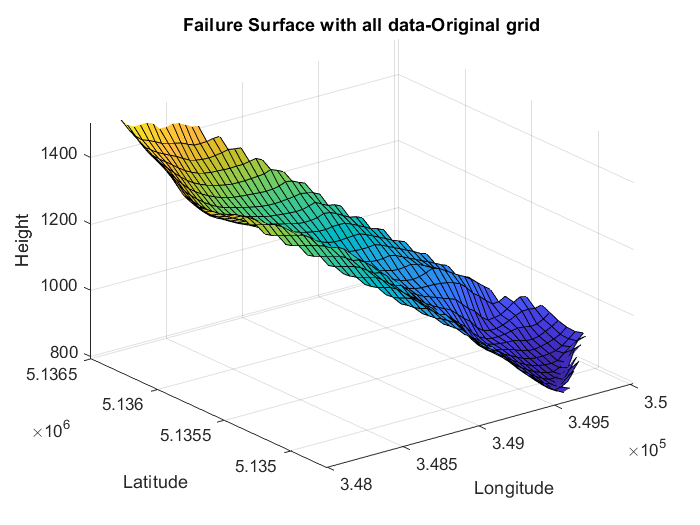



surf(Grid.Xf1, Grid.Yf1, Grid.Zf1);
title('Failure Surface with all data-Original grid');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');
grid on
set(gca, 'ZLim',[min(zout) max(quary.Zts)])

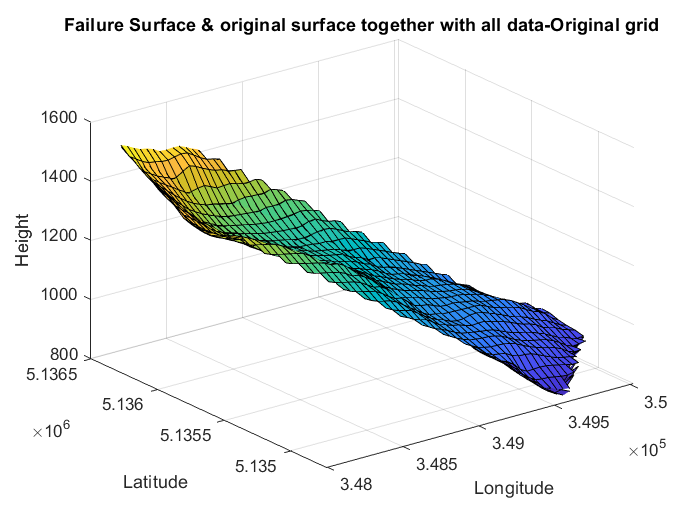

%Failure surface and origina surface with all data 
surf(Grid.Xo1, Grid.Yo1, Grid.Zo1);
title('Failure Surface & original surface together with all data-Original grid');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');

hold on 
surf(Grid.Xf1, Grid.Yf1, Grid.Zf1);
hold off  

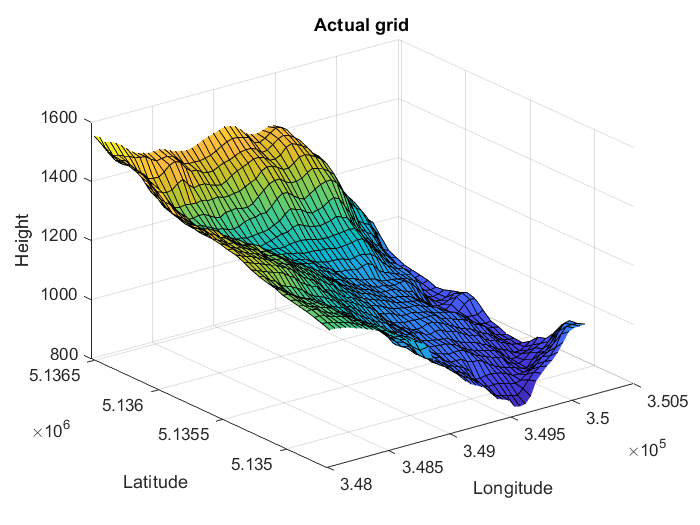



%Ploting the whole grid 
%[X_mesh,Y_mesh] = meshgrid(Grid.x, Grid.y)
figure
grid on

surf(X_mesh, Y_mesh, Z_mesh);
title('Actual grid');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');

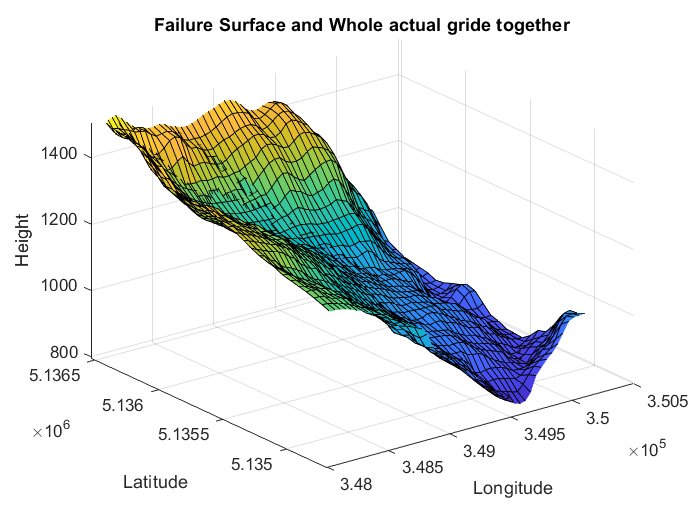


surf(Grid.Xf1, Grid.Yf1, Grid.Zf1);
title('Failure Surface and Whole actual gride together');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');
grid on
set(gca, 'ZLim',[min(zout) max(quary.Zts)])
hold on 
surf(X_mesh, Y_mesh, Z_mesh);
hold off

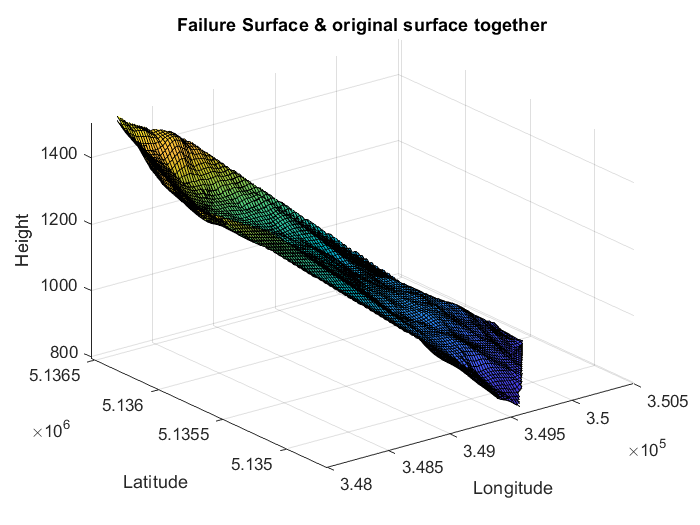

% SurfacePlotting in Original coordinate system with data within contour
% lines

xv = linspace(min(quary.xs), max(quary.xs), 100);
yv = linspace(min(quary.ys), max(quary.ys), 100);
[Xo,Yo] = meshgrid(xv, yv);
Zo = griddata(quary.xs,quary.ys,quary.zs,Xo,Yo);


xv = linspace(min(quary.xs), max(quary.xs), 100);
yv = linspace(min(quary.ys), max(quary.ys), 100);
[Xf,Yf] = meshgrid(xv, yv);
Zf = griddata(quary.xs,quary.ys,bnew,Xf,Yf);

%Failure surface and orinal surface together 
surf(Xo, Yo, Zo);
title('Failure Surface & original surface together');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');

hold on
surf(Xf, Yf, Zf);
hold off
set(gca, 'ZLim',[min(zout) max(quary.Zts)]);

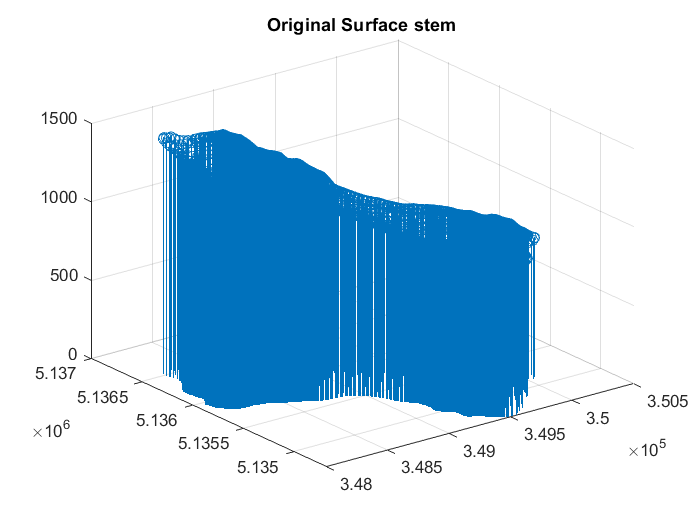

%Plotting after combining the whole data 
%original surface with all data 

figure 
stem3((xycomb(:,1))',(xycomb(:,2))' , zcombd);
title('Original Surface stem');
grid on


xv = linspace(min((xycomb(:,1))), max((xycomb(:,1))), 100);
yv = linspace(min((xycomb(:,2))), max((xycomb(:,2))), 100);
[Xo1,Yo1] = meshgrid(xv, yv);
Zo1 = griddata((xycomb(:,1))',(xycomb(:,2))',zcombd,Xo1,Yo1)

Zo1 =            NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN
           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           Na

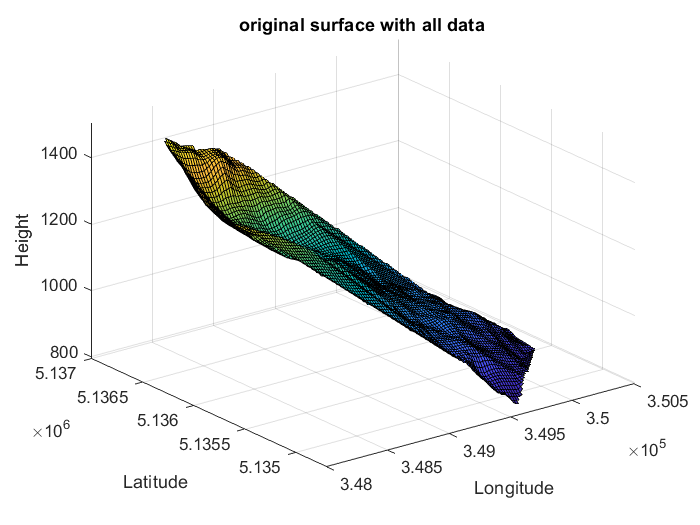


figure
surf(Xo1, Yo1, Zo1);
title('original surface with all data');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');
grid on
set(gca, 'ZLim',[min(zout) max(quary.Zts)])

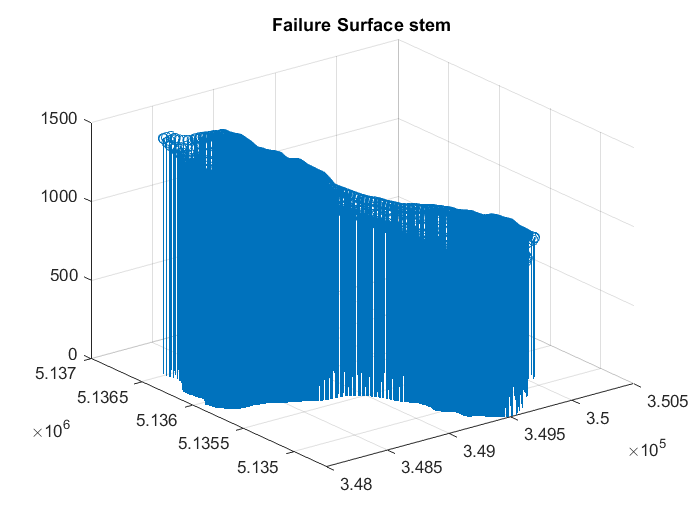


%Failure surface with all data 
figure
stem3((xycomb(:,1))',(xycomb(:,2))' , zcomb);
title('Failure Surface stem');
grid on


xv = linspace(min((xycomb(:,1))), max((xycomb(:,1))), 100)

xv =      348069.99     348090.13     348110.27     348130.40     348150.54     348170.68     348190.82     348210.96     348231.09     348251.23     348271.37     348291.51     348311.65     348331.78     348351.92     348372.06     348392.20     348412.34     348432.47     348452.61     348472.75     348492.89     348513.03     348533.16     348553.30     348573.44     348593.58     348613.72     348633.85     348653.99     348674.13     348694.27     348714.41     348734.54     348754.68     348774.82     348794.96     348815.10     348835.23     348855.37     348875.51     348895.65     348915.79     348935.92     348956.06     348976.20     348996.34     349016.48     349036.61     349056.75


yv = linspace(min((xycomb(:,2))), max((xycomb(:,2))), 100)

yv =     5134672.38    5134691.49    5134710.60    5134729.72    5134748.83    5134767.94    5134787.05    5134806.16    5134825.27    5134844.38    5134863.49    5134882.60    5134901.71    5134920.83    5134939.94    5134959.05    5134978.16    5134997.27    5135016.38    5135035.49    5135054.60    5135073.71    5135092.83    5135111.94    5135131.05    5135150.16    5135169.27    5135188.38    5135207.49    5135226.60    5135245.71    5135264.83    5135283.94    5135303.05    5135322.16    5135341.27    5135360.38    5135379.49    5135398.60    5135417.71    5135436.83    5135455.94    5135475.05    5135494.16    5135513.27    5135532.38    5135551.49    5135570.60    5135589.71    5135608.83


[Xf1,Yf1] = meshgrid(xv, yv);
Zf1 = griddata((xycomb(:,1))',(xycomb(:,2))',zcomb,Xf1,Yf1)

Zf1 =            NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN
           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           Na

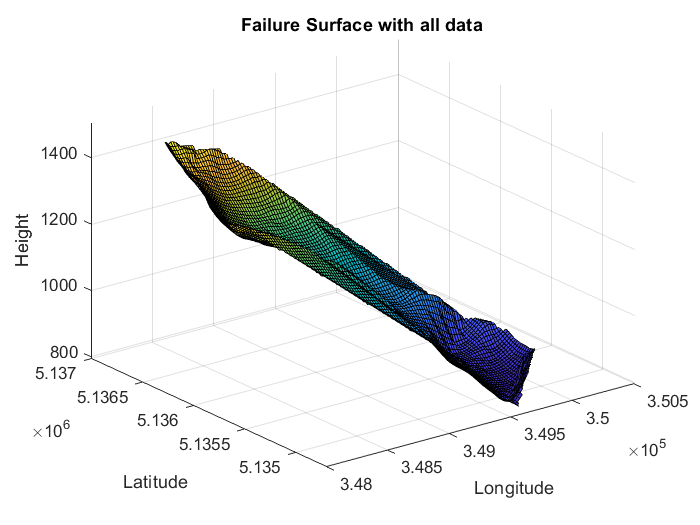



figure
surf(Xf1, Yf1, Zf1);
title('Failure Surface with all data');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');
grid on
set(gca, 'ZLim',[min(zout) max(quary.Zts)])

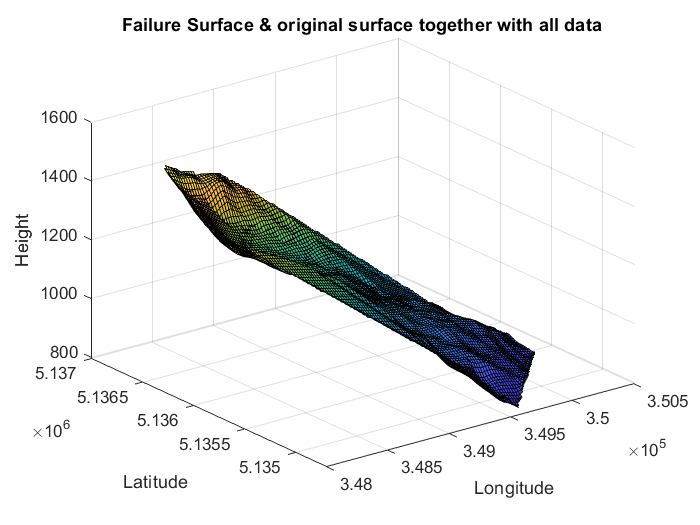


%Failure surface and orinal surface together 
figure
surf(Xo1, Yo1, Zo1);
title('Failure Surface & original surface together with all data');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');

hold on
surf(Xf1, Yf1, Zf1);
hold off


%Ploting the whole grid 

figure
%stem3(xi1, yi1, zi);
grid on

xv = linspace(min(total.x), max(total.x), 100);
yv = linspace(min(total.y), max(total.y), 100);
[X1,Y1] = meshgrid(xv, yv);
Zo = griddata(total.x,total.y,total.z,X1,Y1)

Zo =        1260.00       1260.00       1260.00       1258.73       1257.30       1255.88       1254.45       1252.06       1249.21       1246.09       1242.77       1239.89       1237.52       1234.63       1230.83       1227.15       1223.83       1220.58       1217.73       1214.80       1210.05       1205.30       1198.33       1191.21       1187.64       1184.79       1180.91       1176.64       1170.02       1161.95       1155.82       1151.55       1148.04       1145.67       1142.30       1136.61       1130.36       1121.82       1112.10       1089.79       1067.47       1056.78       1046.33       1041.69       1037.89       1031.55       1024.42       1016.99       1009.39       1001.01
       1263.03       1263.03       1262.78       1261.45       1259.83       1258.30       1256.42       1253.58       1250.93       1248.21       1244.94       1242.31       1239.94       1235.84       1232.04       1228.36       1225.04       1221.79       1218.94       1214.80       1210.05

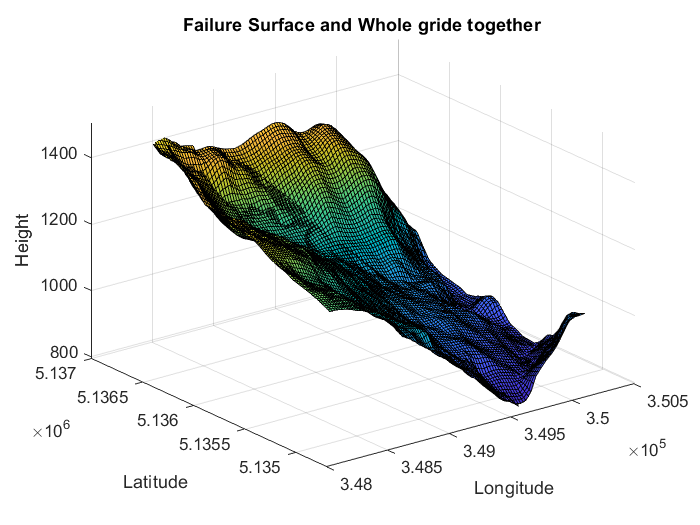


%%Failure Surface and Whole gride together
surf(Xf1, Yf1, Zf1);
hold on
surf(X1, Y1, Zo);
title('Failure Surface and Whole gride together');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height');
grid on
set(gca, 'ZLim',[min(zout) max(quary.Zts)])


%%%%%Saving the required grid data in tiff formate
if ask==1
    keep=keep(1:end-4)
    %Save Original surface    
    orig =append(keep,'_Original_grid.tif')
    %save(orig,'Z_mesh','-mat')
    [Lat_min,Lon_min] = utm2deg(min(total.x),min(total.y),utmzone(1,:));
    [Lat_max,Lon_max] = utm2deg(max(total.x),max(total.y),utmzone(1,:));   
    R = georasterref('RasterSize',size(Z_mesh),'LatitudeLimits',[Lat_min,Lat_max], ...
        'LongitudeLimits',[Lon_min,Lon_max],'ColumnsStartFrom','north');
    geotiffwrite(orig,Z_mesh,R)
    
    
    %Save(filename,variables) save Original failure surface
    orig_fail =append(keep,'_Original_failure_grid.tif');
    gvb=Grid.Zf1;
    %save(orig_fail,'gvb', '-ASCII');
    [Lat_min,Lon_min] = utm2deg(min(Grid.Xf1,[],"all"),min(Grid.Yf1,[],"all"),utmzone(1,:));
    [Lat_max,Lon_max] = utm2deg(max(Grid.Xf1,[],"all"),max(Grid.Yf1,[],"all"),utmzone(1,:));   
    R = georasterref('RasterSize',size(gvb),'LatitudeLimits',[Lat_min,Lat_max], ...
        'LongitudeLimits',[Lon_min,Lon_max]);
    geotiffwrite(orig_fail,gvb,R)
    
    %Save refined whole gride
    refine_whole =append(keep,'_Refined_whole_grid.tif') ;
    %save(refine_whole,'Zo', '-ASCII');
    [Lat_min,Lon_min] = utm2deg(min(X1,[],"all"),min(Y1,[],"all"),utmzone(1,:));
    [Lat_max,Lon_max] = utm2deg(max(X1,[],"all"),max(Y1,[],"all"),utmzone(1,:));    
    R = georasterref('RasterSize',size(Zo),'LatitudeLimits',[Lat_min,Lat_max], ...
        'LongitudeLimits',[Lon_min,Lon_max]);    
    geotiffwrite(refine_whole,Zo,R)    
    
    
    %Save refined original surface
    refine_origin =append(keep,'_Refined_original_grid.tif') ;
    %save(refine_origin,'Zo1', '-ASCII');
    [Lat_min,Lon_min] = utm2deg(min(Xo1,[],"all"),min(Yo1,[],"all"),utmzone(1,:));
    [Lat_max,Lon_max] = utm2deg(max(Xo1,[],"all"),max(Yo1,[],"all"),utmzone(1,:));    
    R = georasterref('RasterSize',size(Zo1),'LatitudeLimits',[Lat_min,Lat_max], ...
        'LongitudeLimits',[Lon_min,Lon_max]);     
    geotiffwrite(refine_origin,Zo1,R)    
    
    %Save refined failure surface
    refine_failure =append(keep,'_Refined_failure_grid.tif') ;
    %save(refine_failure,'Zf1', '-ASCII');
    [Lat_min,Lon_min] = utm2deg(min(Xf1,[],"all"),min(Yf1,[],"all"),utmzone(1,:));
    [Lat_max,Lon_max] = utm2deg(max(Xf1,[],"all"),max(Yf1,[],"all"),utmzone(1,:));    
    R = georasterref('RasterSize',size(Zf1),'LatitudeLimits',[Lat_min,Lat_max], ...
        'LongitudeLimits',[Lon_min,Lon_max]);      
    geotiffwrite(refine_failure,Zf1,R)
    
end

isequal(quary.xs,quary.Xts)

ans = logical
   0



dZ=zeros(1,length(quary.zs))

dZ =              0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0             0


for k=1:length(quary.zs)
    dZ(k)=quary.zs(k)-zout(k);
end

dZ

dZ =          11.33         19.04          2.69          7.78         19.00         19.25          2.62         16.45          3.66         -1.87         39.99          0.22         -5.22         -5.28         27.48          2.16          0.16        -33.41         -6.12         15.13         -1.02        -15.91        -30.36         -2.33         18.10          2.06         -4.51        -31.38        -22.01         21.21         31.00         -4.58        -16.22        -42.82         -9.83         54.41         41.35          0.15         -1.74        -28.91        -35.81          6.03         68.99         29.60          3.92         -0.43        -31.02        -22.59         33.38         67.57


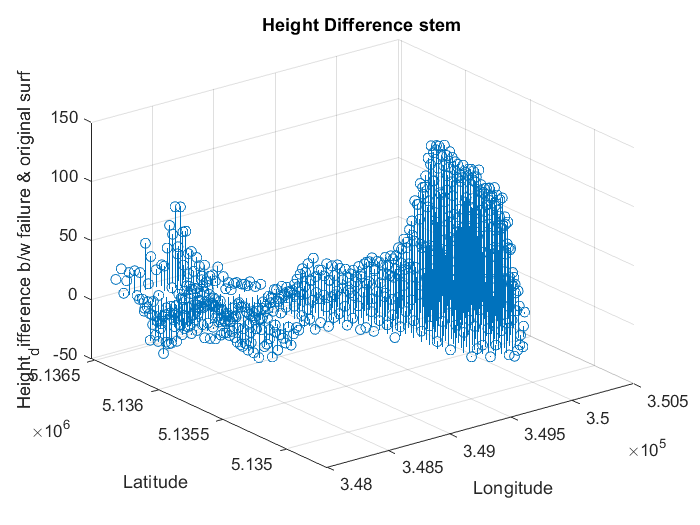

figure
stem3(quary.xs', quary.ys' , dZ);
title('Height Difference stem');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height_difference b/w failure & original surf');
grid on



xv = linspace(min(quary.xs), max(quary.xs), 100);
yv = linspace(min(quary.ys), max(quary.ys), 100);
[Xd,Yd] = meshgrid(xv, yv);
Zd = griddata(quary.xs,quary.ys,dZ,Xd,Yd)

Zd =            NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN
           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN           NaN

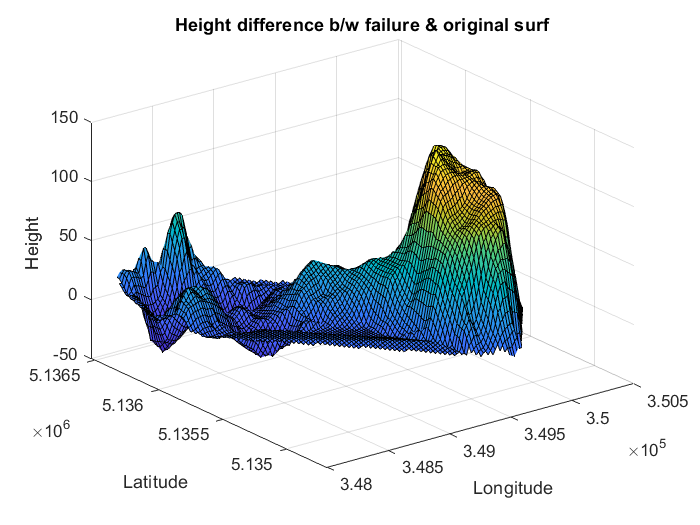


figure
surf(Xd, Yd, Zd);
title('Height difference b/w failure & original surf');
xlabel('Longitude');
ylabel("Latitude");
zlabel('Height ');
grid on



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Calcuation of volume
Xcell_size

Xcell_size =          44.19


Ycell_size

Ycell_size =          61.08


szzx;
szzy;
Volume=0;
for vi=1:length(zout)
    Volume=Volume+Xcell_size*Ycell_size*(quary.zs(vi)-zout(vi));
    Volume;
end
name1 = 'Volume'; 
fprintf('%s = %10.2f  Cubic Meter.\n',name1,Volume)

Volume = 48938901.53  Cubic Meter.



%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

%Calculation of the Area of polygon
Area =polyarea(contor.x,contor.y);
name2= 'Area';
fprintf('%s = %10.2f  Square Meter.\n',name2,Area)

Area = 1487535.93  Square Meter.
